clc,clear all;
close all
syms theta1 theta2 theta3 r0 r1 r2 r3  ;


r1 = 4.5;
r2 = 3.2;
r3 = 4.5;
r0 = 8.8;
th2=[];
th3=[];
w = rad2deg(-0.5)

w = -28.6479


assert (r1 + r2 + r3 > r0,"Not a valid Mechanism")
assert (r0 + r2 + r3 > r1,"Not a valid Mechanism")
assert (r1 + r0 + r3 > r2,"Not a valid Mechanism")
assert (r1 + r2 + r0 > r3,"Not a valid Mechanism")

%Limiting angles for theta 1

theta1max = acos((r0^2 + r1^2 -  ((r3 + r2)^2))/(2*r1*r0))

theta1max = 1.0646

tmd = rad2deg(theta1max)

tmd = 60.9975

tmdi = -tmd

tmdi = -60.9975

time = -(tmd - tmdi)/w

time = 4.2584

t=0:0.01:time

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900





th1=( w*t + tmd)

th1 =    60.9975   60.7110   60.4245   60.1380   59.8515   59.5651   59.2786   58.9921   58.7056   58.4191   58.1327   57.8462   57.5597   57.2732   56.9867   56.7003   56.4138   56.1273   55.8408   55.5544   55.2679   54.9814   54.6949   54.4084   54.1220   53.8355   53.5490   53.2625   52.9760   52.6896   52.4031   52.1166   51.8301   51.5437   51.2572   50.9707   50.6842   50.3977   50.1113   49.8248   49.5383   49.2518   48.9653   48.6789   48.3924   48.1059   47.8194   47.5329   47.2465   46.9600





%Vector loop equations

F(1) = r1*cos(theta1) + r2*cos(theta2) == r0+ r3*cos(theta3)

$$F = \frac{9\,\cos\left(\theta_{1}\right)}{2}+\frac{16\,\cos\left(\theta_{2}\right)}{5}=\frac{9\,\cos\left(\theta_{3}\right)}{2}+\frac{44}{5}$$

F(2) = r1*sin(theta1) + r2*sin(theta2) == 0+ r3*sin(theta3)

$$F = \left(\begin{array}{cc} \frac{9\,\cos\left(\theta_{1}\right)}{2}+\frac{16\,\cos\left(\theta_{2}\right)}{5}=\frac{9\,\cos\left(\theta_{3}\right)}{2}+\frac{44}{5} & \frac{9\,\sin\left(\theta_{1}\right)}{2}+\frac{16\,\sin\left(\theta_{2}\right)}{5}=\frac{9\,\sin\left(\theta_{3}\right)}{2} \end{array}\right)$$


%Create the initial point x0.  

x0 = [360 - (180 - (tmd/2));180 - (tmd/2)]

x0 =   210.4987
  149.5013



    
for i=1:length(th1)

    theta1 = th1(i)
    F = @(x) [+r1*cosd(theta1) + r2*cosd(x(1)) - r3*cosd(x(2)) - r0;
             +r1*sind(theta1) + r2*sind(x(1)) - r3*sind(x(2))];

     
    %Set options to return iterative display.

    options = optimoptions('fsolve','Display','iter');
    
    %Solve the equations.

    [x,fval] = fsolve(F,x0,options);
    th2 = [th2 x(1)] ;
    th3 = [th3 x(2)] ;
    x0 = [double(x(1));double(x(2))]
    disp( "pop")
end

theta1 = 60.9975


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         30.2293                         0.217               1
     1          6         29.6988              1          0.208               1
     2          9         28.4204            2.5          0.186             2.5
     3         12         25.4752           6.25           0.18            6.25
     4         15         18.9924         15.625            0.2            15.6
     5         18         5.34459        39.0625          0.128            39.1
     6         21        0.676775        41.4502         0.0609            97.7
     7         24       0.0217384        15.3757        0.00358            97.7
     8         27      0.00129363        8.17507        0.00044            97.7
     9         30     8.02856e-05        4.02506       4.72e-05            97.7
    10         33     5.01256e-06        2.

x0 =   328.4418
  149.8435


pop


theta1 = 60.7110


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000481393                      5.27e-05               1
     1          6     0.000410759              1       3.68e-05               1
     2          9     0.000128072            2.5        0.00011             2.5
     3         12     7.89526e-06        2.25695          2e-05            6.25
     4         15     6.06404e-09        0.37551        5.6e-07            6.25

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<<a href = "ma

x0 =   324.0513
  152.9551


pop


theta1 = 60.4245


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000502755                      0.000142               1
     1          6      0.00028242              1       0.000688               1
     2          9     3.45893e-06        1.82351       1.72e-05             2.5
     3         12     3.38549e-10       0.182792       1.85e-07            4.56

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   321.8983
  154.4749


pop


theta1 = 60.1380


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000505423                      0.000183               1
     1          6      0.00014325              1       0.000106               1
     2          9     4.12857e-07        1.08204       7.85e-06             2.5
     3         12     2.26863e-12      0.0523565       1.85e-08            2.71

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   320.2390
  155.6437


pop


theta1 = 59.8515


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506181                      0.000213               1
     1          6     0.000141191              1       0.000475               1
     2          9     8.47348e-08       0.740768       4.78e-06             2.5
     3         12     5.37702e-14      0.0205549       3.24e-09             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   318.8369
  156.6298


pop


theta1 = 59.5651


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506239                      0.000237               1
     1          6     0.000169727              1       0.000733               1
     2          9     2.21706e-08       0.538464       3.14e-06             2.5
     3         12     2.31287e-15     0.00936268       7.41e-10             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   317.6000
  157.4989


pop


theta1 = 59.2786


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000257               1
     1          6      8.9665e-05              1        0.00049               1
     2          9     5.65401e-09       0.382853       1.74e-06             2.5
     3         12     1.03627e-16     0.00431177        1.7e-10             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   316.4805
  158.2850


pop


theta1 = 58.9921


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000281               1
     1          6     4.88104e-05              1       0.000345               1
     2          9     1.35283e-09       0.268292       9.26e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   315.4486
  159.0096


pop


theta1 = 58.7056


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000504614                      0.000311               1
     1          6     2.43009e-05              1       0.000246               1
     2          9     2.52571e-10       0.176871       4.36e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   314.4897
  159.6828


pop


theta1 = 58.4191


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000505543                       0.00034               1
     1          6     1.01837e-05              1       0.000163               1
     2          9     3.14971e-11       0.105493       1.68e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   313.5880
  160.3160


pop


theta1 = 58.1327


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506001                      0.000368               1
     1          6     2.65925e-06              1       9.05e-05               1
     2          9     1.07456e-12      0.0456567       3.47e-08             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   312.7346
  160.9158


pop


theta1 = 57.8462


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506203                      0.000395               1
     1          6     1.68684e-07              1       3.14e-05               1
     2          9     1.70413e-15     0.00804564       9.92e-10             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   311.9224
  161.4870


pop


theta1 = 57.5597


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000421               1
     1          6     2.53268e-07       0.970047       1.23e-05               1
     2          9     5.21641e-14       0.020634       5.46e-09            2.43

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   311.1461
  162.0336


pop


theta1 = 57.2732


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506239                      0.000446               1
     1          6     2.12111e-07       0.929296       1.17e-05               1
     2          9     3.10633e-14      0.0181507       4.37e-09            2.32

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   310.4014
  162.5586


pop


theta1 = 56.9867


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506241                       0.00047               1
     1          6     1.80123e-07       0.893342       1.12e-05               1
     2          9      1.9244e-14       0.016125       3.56e-09            2.23

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   309.6848
  163.0645


pop


theta1 = 56.7003


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506243                      0.000494               1
     1          6     1.54768e-07       0.861298       1.07e-05               1
     2          9     1.23296e-14      0.0144467       2.94e-09            2.15

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   308.9933
  163.5535


pop


theta1 = 56.4138


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506244                      0.000517               1
     1          6     1.34334e-07       0.832501       1.03e-05               1
     2          9     8.13229e-15      0.0130377       2.46e-09            2.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   308.3247
  164.0272


pop


theta1 = 56.1273


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506245                      0.000539               1
     1          6     1.17628e-07       0.806431       9.88e-06               1
     2          9     5.50308e-15      0.0118413       2.08e-09            2.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   307.6768
  164.4872


pop


theta1 = 55.8408


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506246                      0.000561               1
     1          6     1.03797e-07       0.782681       9.53e-06               1
     2          9     3.80735e-15      0.0108151       1.78e-09            1.96

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   307.0479
  164.9347


pop


theta1 = 55.5544


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506246                      0.000582               1
     1          6     9.22194e-08       0.760921        9.2e-06               1
     2          9     2.68773e-15     0.00992708       1.53e-09             1.9

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   306.4365
  165.3708


pop


theta1 = 55.2679


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000603               1
     1          6     8.24315e-08       0.740885        8.9e-06               1
     2          9     1.93079e-15     0.00915254       1.33e-09            1.85

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   305.8413
  165.7964


pop


theta1 = 54.9814


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000624               1
     1          6     7.40839e-08       0.722352       8.62e-06               1
     2          9      1.4094e-15     0.00847218       1.16e-09            1.81

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   305.2611
  166.2124


pop


theta1 = 54.6949


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000644               1
     1          6     6.69079e-08       0.705141       8.36e-06               1
     2          9     1.04353e-15     0.00787073       1.02e-09            1.76

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   304.6951
  166.6196


pop


theta1 = 54.4084


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506247                      0.000664               1
     1          6     6.06951e-08       0.689099       8.12e-06               1
     2          9     7.82899e-16     0.00733596       9.01e-10            1.72

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   304.1422
  167.0185


pop


theta1 = 54.1220


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000683               1
     1          6     5.52809e-08       0.674095       7.89e-06               1
     2          9     5.94266e-16     0.00685797          8e-10            1.69

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   303.6017
  167.4097


pop


theta1 = 53.8355


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000703               1
     1          6     5.05351e-08       0.660021       7.67e-06               1
     2          9     4.56151e-16     0.00642871       7.14e-10            1.65

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   303.0728
  167.7938


pop


theta1 = 53.5490


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000722               1
     1          6     4.63518e-08        0.64678       7.46e-06               1
     2          9     3.53649e-16     0.00604146        6.4e-10            1.62

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   302.5551
  168.1712


pop


theta1 = 53.2625


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00074               1
     1          6     4.26465e-08       0.634291       7.27e-06               1
     2          9     2.76727e-16     0.00569074       5.76e-10            1.59

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   302.0478
  168.5424


pop


theta1 = 52.9760


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000759               1
     1          6     3.93492e-08       0.622484       7.08e-06               1
     2          9     2.18351e-16     0.00537189        5.2e-10            1.56

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   301.5504
  168.9078


pop


theta1 = 52.6896


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000777               1
     1          6     3.64027e-08       0.611296        6.9e-06               1
     2          9     1.73649e-16     0.00508103       4.72e-10            1.53

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   301.0626
  169.2676


pop


theta1 = 52.4031


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000795               1
     1          6     3.37589e-08       0.600672       6.73e-06               1
     2          9     1.39128e-16     0.00481483       4.29e-10             1.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   300.5838
  169.6223


pop


theta1 = 52.1166


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                      0.000812               1
     1          6     3.13783e-08       0.590565       6.57e-06               1
     2          9     1.12222e-16     0.00457049       3.91e-10            1.48

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   300.1136
  169.9721


pop


theta1 = 51.8301


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506248                       0.00083               1
     1          6     2.92274e-08       0.580932       6.41e-06               1
     2          9     9.11287e-17     0.00434559       3.57e-10            1.45

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   299.6518
  170.3173


pop


theta1 = 51.5437


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000847               1
     1          6     2.72776e-08       0.571735       6.26e-06               1
     2          9     7.44551e-17     0.00413803       3.28e-10            1.43

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   299.1979
  170.6581


pop


theta1 = 51.2572


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000864               1
     1          6      2.5505e-08       0.562941       6.11e-06               1
     2          9     6.11294e-17     0.00394601       3.01e-10            1.41

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   298.7517
  170.9949


pop


theta1 = 50.9707


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00088               1
     1          6      2.3889e-08       0.554519       5.97e-06               1
     2          9      5.0467e-17     0.00376798       2.78e-10            1.39

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   298.3129
  171.3277


pop


theta1 = 50.6842


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000897               1
     1          6      2.2412e-08       0.546441       5.83e-06               1
     2          9     4.18966e-17     0.00360256       2.57e-10            1.37

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   297.8813
  171.6568


pop


theta1 = 50.3977


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000913               1
     1          6     2.10584e-08       0.538685        5.7e-06               1
     2          9      3.4925e-17     0.00344853       2.37e-10            1.35

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   297.4565
  171.9825


pop


theta1 = 50.1113


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000929               1
     1          6     1.98153e-08       0.531227       5.57e-06               1
     2          9     2.92605e-17     0.00330485        2.2e-10            1.33

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   297.0384
  172.3048


pop


theta1 = 49.8248


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000945               1
     1          6     1.86712e-08       0.524047       5.45e-06               1
     2          9     2.46308e-17     0.00317059       2.05e-10            1.31

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   296.6267
  172.6240


pop


theta1 = 49.5383


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000961               1
     1          6     1.76159e-08       0.517127       5.33e-06               1
     2          9     2.08032e-17     0.00304491       1.91e-10            1.29

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   296.2214
  172.9401


pop


theta1 = 49.2518


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000977               1
     1          6     1.66407e-08       0.510451       5.21e-06               1
     2          9     1.76224e-17     0.00292708       1.78e-10            1.28

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   295.8221
  173.2534


pop


theta1 = 48.9653


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000992               1
     1          6     1.57379e-08       0.504003       5.09e-06               1
     2          9     1.49995e-17     0.00281645       1.66e-10            1.26

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   295.4287
  173.5640


pop


theta1 = 48.6789


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     1.49007e-08       0.497769       4.98e-06               1
     2          9     1.28052e-17     0.00271243       1.56e-10            1.24

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   295.0411
  173.8719


pop


theta1 = 48.3924


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6      1.4123e-08       0.491738       4.87e-06               1
     2          9     1.09707e-17     0.00261449       1.46e-10            1.23

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   294.6591
  174.1775


pop


theta1 = 48.1059


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     1.33996e-08       0.485896       4.77e-06               1
     2          9     9.43298e-18     0.00252216       1.37e-10            1.21

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   294.2826
  174.4806


pop


theta1 = 47.8194


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     1.27255e-08       0.480233       4.66e-06               1
     2          9     8.13054e-18     0.00243502       1.29e-10             1.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 =   293.9115
  174.7815


pop


theta1 = 47.5329


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     1.20967e-08        0.47474       4.56e-06               1
     2          9     7.03282e-18     0.00235268       1.22e-10            1.19

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.5456
  175.0803


pop


theta1 = 47.2465


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     1.15093e-08       0.469407       4.46e-06               1
     2          9      6.0997e-18      0.0022748       1.15e-10            1.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.1848
  175.3770


pop


theta1 = 46.9600


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6       1.096e-08       0.464227       4.36e-06               1
     2          9     5.30585e-18     0.00220106       1.08e-10            1.16

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.8290
  175.6718


pop


theta1 = 46.6735


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     1.04456e-08       0.459189       4.27e-06               1
     2          9     4.62379e-18     0.00213118       1.02e-10            1.15

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.4782
  175.9647


pop


theta1 = 46.3870


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     9.96339e-09       0.454289       4.17e-06               1
     2          9     4.04633e-18      0.0020649       9.71e-11            1.14

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.1321
  176.2559


pop


theta1 = 46.1006


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     9.51093e-09       0.449519       4.08e-06               1
     2          9      3.5444e-18     0.00200197       9.22e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.7908
  176.5453


pop


theta1 = 45.8141


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     9.08603e-09       0.444872       3.99e-06               1
     2          9     3.11661e-18     0.00194219       8.76e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.4542
  176.8332


pop


theta1 = 45.5276


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     8.68658e-09       0.440344        3.9e-06               1
     2          9     2.74719e-18     0.00188535       8.33e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.1221
  177.1195


pop


theta1 = 45.2411


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     8.31071e-09       0.435928       3.81e-06               1
     2          9     2.42377e-18     0.00183127       7.93e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.7945
  177.4044


pop


theta1 = 44.9546


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     7.95685e-09       0.431619       3.73e-06               1
     2          9     2.14614e-18     0.00177979       7.57e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.4714
  177.6878


pop


theta1 = 44.6682


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6      7.6234e-09       0.427414       3.64e-06               1
     2          9     1.90395e-18     0.00173076       7.23e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.1526
  177.9699


pop


theta1 = 44.3817


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     7.30899e-09       0.423307       3.56e-06               1
     2          9     1.69371e-18     0.00168403       6.91e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.8381
  178.2508


pop


theta1 = 44.0952


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     7.01236e-09       0.419294       3.48e-06               1
     2          9      1.5097e-18     0.00163948       6.61e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.5279
  178.5305


pop


theta1 = 43.8087


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.73236e-09       0.415371        3.4e-06               1
     2          9     1.34924e-18     0.00159698       6.34e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.2218
  178.8090


pop


theta1 = 43.5222


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.46785e-09       0.411536       3.32e-06               1
     2          9     1.20659e-18     0.00155643       6.09e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.9200
  179.0864


pop


theta1 = 43.2358


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.21797e-09       0.407784       3.24e-06               1
     2          9     1.08299e-18     0.00151774       5.85e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.6222
  179.3628


pop


theta1 = 42.9493


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00128               1
     1          6     5.98173e-09       0.404113       3.16e-06               1
     2          9     9.75455e-19     0.00148079       5.63e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.3284
  179.6382


pop


theta1 = 42.6628


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00129               1
     1          6     5.75833e-09       0.400519       3.09e-06               1
     2          9     8.79282e-19     0.00144551       5.42e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.0387
  179.9127


pop


theta1 = 42.3763


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0013               1
     1          6       5.547e-09          0.397       3.02e-06               1
     2          9     7.95198e-19     0.00141181       5.23e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.7529
  180.1863


pop


theta1 = 42.0898


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00131               1
     1          6     5.34707e-09       0.393554       2.94e-06               1
     2          9     7.18889e-19     0.00137963       5.04e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.4711
  180.4590


pop


theta1 = 41.8034


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00132               1
     1          6     5.15781e-09       0.390177       2.87e-06               1
     2          9      6.5406e-19     0.00134889       4.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.1932
  180.7310


pop


theta1 = 41.5169


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00134               1
     1          6     4.97876e-09       0.386868        2.8e-06               1
     2          9     5.95248e-19     0.00131953       4.72e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.9191
  181.0022


pop


theta1 = 41.2304


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00135               1
     1          6     4.80924e-09       0.383625       2.73e-06               1
     2          9     5.43686e-19     0.00129149       4.57e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.6488
  181.2727


pop


theta1 = 40.9439


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00136               1
     1          6     4.64876e-09       0.380445       2.71e-06               1
     2          9     4.97326e-19     0.00126471       4.43e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.3824
  181.5426


pop


theta1 = 40.6575


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00137               1
     1          6     4.49686e-09       0.377328        2.7e-06               1
     2          9     4.55721e-19     0.00123915        4.3e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.1198
  181.8118


pop


theta1 = 40.3710


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00138               1
     1          6     4.35308e-09        0.37427        2.7e-06               1
     2          9     4.19746e-19     0.00121475       4.18e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.8609
  182.0805


pop


theta1 = 40.0845


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00139               1
     1          6     4.21706e-09       0.371272       2.69e-06               1
     2          9     3.87263e-19     0.00119148       4.07e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.6057
  182.3486


pop


theta1 = 39.7980


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0014               1
     1          6     4.08835e-09        0.36833       2.69e-06               1
     2          9     3.58035e-19     0.00116928       3.96e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.3542
  182.6163


pop


theta1 = 39.5115


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00141               1
     1          6     3.96662e-09       0.365445       2.68e-06               1
     2          9     3.32339e-19     0.00114813       3.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.1065
  182.8834


pop


theta1 = 39.2251


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00142               1
     1          6     3.85153e-09       0.362614       2.68e-06               1
     2          9     3.08817e-19     0.00112798       3.77e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.8624
  183.1501


pop


theta1 = 38.9386


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00143               1
     1          6     3.74274e-09       0.359836       2.68e-06               1
     2          9     2.87958e-19      0.0011088       3.68e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.6219
  183.4165


pop


theta1 = 38.6521


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00144               1
     1          6     3.64003e-09       0.357111       2.67e-06               1
     2          9      2.6971e-19     0.00109057       3.61e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.3851
  183.6824


pop


theta1 = 38.3656


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00145               1
     1          6     3.54307e-09       0.354438       2.67e-06               1
     2          9     2.53049e-19     0.00107324       3.53e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.1520
  183.9481


pop


theta1 = 38.0791


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00146               1
     1          6     3.45158e-09       0.351815       2.67e-06               1
     2          9     2.38293e-19      0.0010568       3.46e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.9224
  184.2134


pop


theta1 = 37.7927


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00147               1
     1          6     3.36538e-09       0.349241       2.67e-06               1
     2          9     2.25261e-19     0.00104121        3.4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.6964
  184.4784


pop


theta1 = 37.5062


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00148               1
     1          6     3.28424e-09       0.346717       2.66e-06               1
     2          9     2.13377e-19     0.00102645       3.34e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.4741
  184.7433


pop


theta1 = 37.2197


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00149               1
     1          6     3.20793e-09       0.344242       2.66e-06               1
     2          9     2.02927e-19     0.00101251       3.28e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.2553
  185.0079


pop


theta1 = 36.9332


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0015               1
     1          6     3.13623e-09       0.341814       2.66e-06               1
     2          9     1.93155e-19    0.000999353       3.23e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.0401
  185.2723


pop


theta1 = 36.6467


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00151               1
     1          6     3.06897e-09       0.339433       2.66e-06               1
     2          9     1.84958e-19    0.000986959       3.19e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.8285
  185.5366


pop


theta1 = 36.3603


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00152               1
     1          6       3.006e-09         0.3371       2.66e-06               1
     2          9     1.77011e-19    0.000975317       3.14e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.6204
  185.8008


pop


theta1 = 36.0738


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00152               1
     1          6     2.94712e-09       0.334813       2.66e-06               1
     2          9     1.70589e-19    0.000964401        3.1e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.4159
  186.0648


pop


theta1 = 35.7873


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     2.89217e-09       0.332572       2.66e-06               1
     2          9     1.64586e-19    0.000954192       3.06e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.2149
  186.3288


pop


theta1 = 35.5008


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00154               1
     1          6     2.84102e-09       0.330377       2.66e-06               1
     2          9     1.59149e-19    0.000944676       3.03e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.0175
  186.5928


pop


theta1 = 35.2144


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00155               1
     1          6     2.79353e-09       0.328228       2.66e-06               1
     2          9     1.54545e-19    0.000935838          3e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.8237
  186.8567


pop


theta1 = 34.9279


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00156               1
     1          6     2.74956e-09       0.326124       2.67e-06               1
     2          9     1.50495e-19    0.000927661       2.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.6334
  187.1206


pop


theta1 = 34.6414


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     2.70898e-09       0.324066       2.67e-06               1
     2          9     1.46853e-19    0.000920125       2.95e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.4467
  187.3846


pop


theta1 = 34.3549


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     2.67168e-09       0.322054       2.67e-06               1
     2          9     1.43865e-19    0.000913221       2.93e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.2635
  187.6486


pop


theta1 = 34.0684


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00158               1
     1          6      2.6375e-09       0.320087       2.67e-06               1
     2          9      1.4121e-19    0.000906926       2.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.0838
  187.9127


pop


theta1 = 33.7820


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00159               1
     1          6     2.60642e-09       0.318166       2.67e-06               1
     2          9     1.38864e-19    0.000901237        2.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.9077
  188.1769


pop


theta1 = 33.4955


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0016               1
     1          6     2.57824e-09        0.31629       2.68e-06               1
     2          9     1.36876e-19    0.000896127       2.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.7352
  188.4412


pop


theta1 = 33.2090


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0016               1
     1          6      2.5529e-09        0.31446       2.68e-06               1
     2          9     1.35427e-19    0.000891589       2.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.5663
  188.7057


pop


theta1 = 32.9225


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     2.53032e-09       0.312676       2.68e-06               1
     2          9       1.341e-19    0.000887608       2.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.4009
  188.9703


pop


theta1 = 32.6360


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00162               1
     1          6      2.5104e-09       0.310939       2.69e-06               1
     2          9     1.33241e-19    0.000884172       2.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.2391
  189.2351


pop


theta1 = 32.3496


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00162               1
     1          6     2.49305e-09       0.309248       2.69e-06               1
     2          9     1.32661e-19    0.000881266       2.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.0808
  189.5001


pop


theta1 = 32.0631


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     2.47818e-09       0.307604        2.7e-06               1
     2          9     1.32138e-19    0.000878875       2.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.9262
  189.7654


pop


theta1 = 31.7766


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00164               1
     1          6     2.46569e-09       0.306007        2.7e-06               1
     2          9     1.32101e-19    0.000876983       2.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.7751
  190.0308


pop


theta1 = 31.4901


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00164               1
     1          6     2.45553e-09       0.304457       2.71e-06               1
     2          9     1.32114e-19    0.000875581       2.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.6277
  190.2966


pop


theta1 = 31.2036


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     2.44763e-09       0.302956       2.71e-06               1
     2          9     1.32441e-19    0.000874655       2.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.4838
  190.5626


pop


theta1 = 30.9172


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00166               1
     1          6     2.44188e-09       0.301503       2.72e-06               1
     2          9     1.33008e-19    0.000874187       2.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.3436
  190.8290


pop


theta1 = 30.6307


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00166               1
     1          6     2.43823e-09       0.300099       2.72e-06               1
     2          9     1.33821e-19    0.000874168       2.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.2070
  191.0956


pop


theta1 = 30.3442


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     2.43663e-09       0.298745       2.73e-06               1
     2          9     1.34664e-19    0.000874585       2.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.0740
  191.3626


pop


theta1 = 30.0577


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     2.43697e-09        0.29744       2.74e-06               1
     2          9     1.35858e-19     0.00087542       2.89e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.9447
  191.6300


pop


theta1 = 29.7713


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     2.43921e-09       0.296186       2.74e-06               1
     2          9     1.37088e-19    0.000876662        2.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.8191
  191.8977


pop


theta1 = 29.4848


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     2.44328e-09       0.294983       2.75e-06               1
     2          9     1.38683e-19    0.000878298       2.92e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.6971
  192.1659


pop


theta1 = 29.1983


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     2.44911e-09       0.293832       2.76e-06               1
     2          9     1.40363e-19    0.000880311       2.94e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.5788
  192.4344


pop


theta1 = 28.9118


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     2.45664e-09       0.292733       2.76e-06               1
     2          9     1.42322e-19    0.000882689       2.96e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.4642
  192.7033


pop


theta1 = 28.6253


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     2.46583e-09       0.291687       2.77e-06               1
     2          9     1.44229e-19    0.000885424       2.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.3533
  192.9727


pop


theta1 = 28.3389


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     2.47657e-09       0.290694       2.78e-06               1
     2          9     1.46464e-19    0.000888493       2.99e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.2461
  193.2426


pop


theta1 = 28.0524


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     2.48882e-09       0.289756       2.79e-06               1
     2          9      1.4889e-19    0.000891883       3.02e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.1426
  193.5129


pop


theta1 = 27.7659


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     2.50253e-09       0.288872       2.79e-06               1
     2          9     1.51378e-19    0.000895586       3.04e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.0429
  193.7836


pop


theta1 = 27.4794


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     2.51765e-09       0.288043        2.8e-06               1
     2          9     1.54118e-19    0.000899587       3.07e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.9470
  194.0549


pop


theta1 = 27.1929


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     2.53414e-09       0.287271       2.81e-06               1
     2          9     1.56987e-19    0.000903878       3.09e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.8548
  194.3267


pop


theta1 = 26.9065


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     2.55188e-09       0.286555       2.82e-06               1
     2          9     1.59984e-19    0.000908432       3.12e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.7664
  194.5990


pop


theta1 = 26.6200


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     2.57081e-09       0.285896       2.83e-06               1
     2          9     1.63266e-19    0.000913237       3.15e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.6818
  194.8719


pop


theta1 = 26.3335


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     2.59097e-09       0.285296       2.84e-06               1
     2          9     1.66528e-19    0.000918296       3.18e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.6010
  195.1453


pop


theta1 = 26.0470


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     2.61219e-09       0.284753       2.85e-06               1
     2          9     1.70026e-19    0.000923577       3.21e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.5241
  195.4192


pop


theta1 = 25.7605


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     2.63448e-09        0.28427       2.86e-06               1
     2          9     1.73752e-19    0.000929076       3.24e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.4510
  195.6938


pop


theta1 = 25.4741


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     2.65775e-09       0.283846       2.86e-06               1
     2          9     1.77575e-19    0.000934776       3.28e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.3818
  195.9689


pop


theta1 = 25.1876


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     2.68194e-09       0.283482       2.87e-06               1
     2          9     1.81529e-19    0.000940663       3.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.3165
  196.2446


pop


theta1 = 24.9011


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     2.70703e-09       0.283179       2.88e-06               1
     2          9     1.85712e-19     0.00094673       3.35e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.2550
  196.5209


pop


theta1 = 24.6146


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     2.73292e-09       0.282937       2.89e-06               1
     2          9     1.90058e-19    0.000952955       3.38e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.1975
  196.7978


pop


theta1 = 24.3282


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     2.75957e-09       0.282756        2.9e-06               1
     2          9     1.94448e-19     0.00095933       3.42e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.1439
  197.0753


pop


theta1 = 24.0417


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     2.78693e-09       0.282638       2.91e-06               1
     2          9     1.99171e-19    0.000965842       3.46e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0942
  197.3535


pop


theta1 = 23.7552


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.81493e-09       0.282581       2.92e-06               1
     2          9     2.04027e-19    0.000972476        3.5e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0485
  197.6323


pop


theta1 = 23.4687


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.84349e-09       0.282587       2.93e-06               1
     2          9     2.08875e-19    0.000979214       3.54e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0068
  197.9118


pop


theta1 = 23.1822


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.87261e-09       0.282656       2.95e-06               1
     2          9     2.13999e-19    0.000986056       3.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9691
  198.1919


pop


theta1 = 22.8958


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.90219e-09       0.282789       2.96e-06               1
     2          9     2.19197e-19    0.000992977       3.62e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9354
  198.4727


pop


theta1 = 22.6093


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.93215e-09       0.282984       2.97e-06               1
     2          9     2.24581e-19    0.000999967       3.66e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9057
  198.7541


pop


theta1 = 22.3228


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.96246e-09       0.283243       2.98e-06               1
     2          9     2.30019e-19     0.00100701        3.7e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8800
  199.0362


pop


theta1 = 22.0363


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     2.99308e-09       0.283566       2.99e-06               1
     2          9     2.35667e-19      0.0010141       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8584
  199.3191


pop


theta1 = 21.7498


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.02388e-09       0.283952          3e-06               1
     2          9     2.41434e-19     0.00102122       3.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8409
  199.6026


pop


theta1 = 21.4634


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.05488e-09       0.284401       3.01e-06               1
     2          9     2.47345e-19     0.00102836       3.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8275
  199.8867


pop


theta1 = 21.1769


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.08597e-09       0.284915       3.02e-06               1
     2          9     2.53448e-19      0.0010355       3.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8182
  200.1716


pop


theta1 = 20.8904


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.11712e-09       0.285491       3.03e-06               1
     2          9     2.59431e-19     0.00104263       3.92e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8130
  200.4572


pop


theta1 = 20.6039


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.14826e-09       0.286131       3.04e-06               1
     2          9     2.65797e-19     0.00104974       3.97e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8119
  200.7435


pop


theta1 = 20.3175


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.17928e-09       0.286833       3.06e-06               1
     2          9     2.72086e-19     0.00105681       4.01e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8150
  201.0305


pop


theta1 = 20.0310


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6      3.2102e-09       0.287598       3.07e-06               1
     2          9     2.78571e-19     0.00106384       4.05e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8222
  201.3183


pop


theta1 = 19.7445


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.24092e-09       0.288425       3.08e-06               1
     2          9     2.84962e-19      0.0010708        4.1e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8337
  201.6067


pop


theta1 = 19.4580


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.27139e-09       0.289314       3.09e-06               1
     2          9     2.91651e-19     0.00107769       4.14e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8493
  201.8958


pop


theta1 = 19.1715


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00177               1
     1          6     3.30156e-09       0.290265        3.1e-06               1
     2          9     2.98266e-19      0.0010845       4.18e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8692
  202.1857


pop


theta1 = 18.8851


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.33136e-09       0.291275       3.11e-06               1
     2          9     3.05107e-19      0.0010912       4.23e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.8933
  202.4762


pop


theta1 = 18.5986


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.36072e-09       0.292346       3.12e-06               1
     2          9      3.1192e-19     0.00109779       4.27e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9216
  202.7675


pop


theta1 = 18.3121


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.38958e-09       0.293476       3.13e-06               1
     2          9     3.18517e-19     0.00110425       4.31e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9541
  203.0595


pop


theta1 = 18.0256


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.41793e-09       0.294664       3.15e-06               1
     2          9     3.25142e-19     0.00111058       4.36e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  276.9910
  203.3522


pop


theta1 = 17.7391


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.44567e-09        0.29591       3.16e-06               1
     2          9     3.32047e-19     0.00111676        4.4e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0321
  203.6456


pop


theta1 = 17.4527


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.47278e-09       0.297213       3.17e-06               1
     2          9     3.38655e-19     0.00112277       4.44e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.0775
  203.9397


pop


theta1 = 17.1662


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00176               1
     1          6     3.49915e-09       0.298571       3.18e-06               1
     2          9     3.45187e-19     0.00112861       4.47e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.1272
  204.2345


pop


theta1 = 16.8797


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.52481e-09       0.299984       3.19e-06               1
     2          9     3.51877e-19     0.00113426       4.51e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.1813
  204.5300


pop


theta1 = 16.5932


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.54966e-09       0.301451        3.2e-06               1
     2          9     3.58432e-19     0.00113971       4.55e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.2396
  204.8262


pop


theta1 = 16.3067


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.57362e-09       0.302971       3.21e-06               1
     2          9     3.64854e-19     0.00114494       4.59e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.3023
  205.1231


pop


theta1 = 16.0203


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00175               1
     1          6     3.59673e-09       0.304541       3.22e-06               1
     2          9     3.70914e-19     0.00114995       4.62e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.3693
  205.4206


pop


theta1 = 15.7338


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6      3.6189e-09       0.306162       3.23e-06               1
     2          9     3.77417e-19     0.00115473       4.65e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.4407
  205.7188


pop


theta1 = 15.4473


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.64006e-09       0.307832       3.24e-06               1
     2          9     3.83294e-19     0.00115925       4.68e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.5165
  206.0177


pop


theta1 = 15.1608


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00174               1
     1          6     3.66016e-09       0.309549       3.25e-06               1
     2          9     3.88929e-19     0.00116351       4.71e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.5966
  206.3172


pop


theta1 = 14.8744


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6      3.6793e-09       0.311312       3.26e-06               1
     2          9     3.94675e-19     0.00116751       4.74e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.6811
  206.6174


pop


theta1 = 14.5879


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.69726e-09        0.31312       3.27e-06               1
     2          9      4.0013e-19     0.00117121       4.77e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.7699
  206.9182


pop


theta1 = 14.3014


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00173               1
     1          6     3.71413e-09       0.314971       3.28e-06               1
     2          9     4.05258e-19     0.00117463       4.79e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.8632
  207.2196


pop


theta1 = 14.0149


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.72984e-09       0.316863       3.29e-06               1
     2          9     4.10366e-19     0.00117775       4.82e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  277.9609
  207.5216


pop


theta1 = 13.7284


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00172               1
     1          6     3.74432e-09       0.318795        3.3e-06               1
     2          9     4.14627e-19     0.00118054       4.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.0629
  207.8243


pop


theta1 = 13.4420


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.75764e-09       0.320766       3.31e-06               1
     2          9     4.18896e-19     0.00118302       4.85e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.1694
  208.1275


pop


theta1 = 13.1555


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00171               1
     1          6     3.76969e-09       0.322773       3.32e-06               1
     2          9     4.22822e-19     0.00118516       4.87e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.2802
  208.4312


pop


theta1 = 12.8690


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6     3.78055e-09       0.324816       3.32e-06               1
     2          9     4.26265e-19     0.00118696       4.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.3955
  208.7356


pop


theta1 = 12.5825


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0017               1
     1          6      3.7901e-09       0.326892       3.33e-06               1
     2          9     4.29742e-19      0.0011884       4.89e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.5152
  209.0404


pop


theta1 = 12.2960


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.79839e-09       0.328999       3.34e-06               1
     2          9     4.32293e-19     0.00118949        4.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.6392
  209.3458


pop


theta1 = 12.0096


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00169               1
     1          6     3.80542e-09       0.331136       3.35e-06               1
     2          9     4.34612e-19     0.00119021       4.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.7677
  209.6517


pop


theta1 = 11.7231


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.81118e-09       0.333301       3.35e-06               1
     2          9      4.3665e-19     0.00119055       4.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  278.9006
  209.9581


pop


theta1 = 11.4366


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00168               1
     1          6     3.81563e-09       0.335492       3.36e-06               1
     2          9     4.37833e-19     0.00119051       4.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.0379
  210.2649


pop


theta1 = 11.1501


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     3.81885e-09       0.337707       3.36e-06               1
     2          9     4.38635e-19     0.00119008        4.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.1796
  210.5722


pop


theta1 = 10.8636


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00167               1
     1          6     3.82078e-09       0.339945       3.37e-06               1
     2          9     4.39126e-19     0.00118926        4.9e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.3256
  210.8799


pop


theta1 = 10.5772


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00166               1
     1          6      3.8215e-09       0.342203       3.38e-06               1
     2          9     4.39179e-19     0.00118804       4.89e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.4761
  211.1880


pop


theta1 = 10.2907


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.82095e-09        0.34448       3.38e-06               1
     2          9     4.38289e-19     0.00118641       4.88e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.6309
  211.4965


pop


theta1 = 10.0042


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00165               1
     1          6     3.81922e-09       0.346774       3.38e-06               1
     2          9     4.37083e-19     0.00118437       4.86e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.7901
  211.8053


pop


theta1 = 9.7177


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00164               1
     1          6     3.81632e-09       0.349082       3.39e-06               1
     2          9     4.35279e-19     0.00118193       4.84e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  279.9537
  212.1145


pop


theta1 = 9.4313


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.81226e-09       0.351404       3.39e-06               1
     2          9     4.32812e-19     0.00117907       4.82e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.1216
  212.4240


pop


theta1 = 9.1448


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00163               1
     1          6     3.80711e-09       0.353736       3.39e-06               1
     2          9     4.29971e-19      0.0011758        4.8e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.2938
  212.7337


pop


theta1 = 8.8583


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00162               1
     1          6     3.80092e-09       0.356076        3.4e-06               1
     2          9     4.26453e-19     0.00117211       4.77e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.4704
  213.0437


pop


theta1 = 8.5718


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00161               1
     1          6     3.79365e-09       0.358424        3.4e-06               1
     2          9     4.22493e-19       0.001168       4.74e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.6513
  213.3540


pop


theta1 = 8.2853


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0016               1
     1          6     3.78546e-09       0.360777        3.4e-06               1
     2          9     4.17735e-19     0.00116348       4.71e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  280.8365
  213.6644


pop


theta1 = 7.9989


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00159               1
     1          6      3.7763e-09       0.363133        3.4e-06               1
     2          9     4.12227e-19     0.00115855       4.67e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.0260
  213.9750


pop


theta1 = 7.7124


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00159               1
     1          6     3.76632e-09        0.36549        3.4e-06               1
     2          9     4.06309e-19      0.0011532       4.63e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.2197
  214.2857


pop


theta1 = 7.4259


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00158               1
     1          6     3.75554e-09       0.367846        3.4e-06               1
     2          9     4.00026e-19     0.00114746       4.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.4177
  214.5966


pop


theta1 = 7.1394


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00157               1
     1          6     3.74403e-09         0.3702        3.4e-06               1
     2          9     3.92986e-19     0.00114131       4.54e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.6200
  214.9075


pop


theta1 = 6.8529


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00156               1
     1          6     3.73183e-09       0.372548        3.4e-06               1
     2          9     3.85588e-19     0.00113476       4.49e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  281.8264
  215.2184


pop


theta1 = 6.5665


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00155               1
     1          6     3.71905e-09        0.37489        3.4e-06               1
     2          9      3.7726e-19     0.00112783       4.43e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.0370
  215.5294


pop


theta1 = 6.2800


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00154               1
     1          6      3.7058e-09       0.377224       3.39e-06               1
     2          9     3.68716e-19     0.00112052       4.37e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.2518
  215.8403


pop


theta1 = 5.9935


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     3.69208e-09       0.379547       3.39e-06               1
     2          9     3.59848e-19     0.00111284       4.32e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.4708
  216.1512


pop


theta1 = 5.7070


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00153               1
     1          6     3.67798e-09       0.381857       3.38e-06               1
     2          9     3.50219e-19     0.00110479       4.26e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.6938
  216.4619


pop


theta1 = 5.4205


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00152               1
     1          6     3.66366e-09       0.384154       3.38e-06               1
     2          9     3.40111e-19      0.0010964       4.19e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  282.9210
  216.7726


pop


theta1 = 5.1341


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00151               1
     1          6     3.64918e-09       0.386434       3.37e-06               1
     2          9     3.29757e-19     0.00108768       4.12e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.1522
  217.0830


pop


theta1 = 4.8476


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0015               1
     1          6     3.63457e-09       0.388697       3.37e-06               1
     2          9     3.19114e-19     0.00107863       4.05e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.3874
  217.3933


pop


theta1 = 4.5611


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00149               1
     1          6     3.61998e-09       0.390941       3.36e-06               1
     2          9     3.07899e-19     0.00106928       3.98e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.6267
  217.7033


pop


theta1 = 4.2746


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00148               1
     1          6     3.60549e-09       0.393162       3.35e-06               1
     2          9      2.9658e-19     0.00105964       3.91e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  283.8699
  218.0130


pop


theta1 = 3.9882


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00147               1
     1          6     3.59122e-09       0.395361       3.34e-06               1
     2          9     2.84795e-19     0.00104973       3.83e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.1170
  218.3223


pop


theta1 = 3.7017


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00146               1
     1          6     3.57722e-09       0.397535       3.33e-06               1
     2          9     2.72869e-19     0.00103957       3.75e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.3681
  218.6313


pop


theta1 = 3.4152


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00145               1
     1          6     3.56361e-09       0.399683       3.32e-06               1
     2          9     2.60951e-19     0.00102919       3.67e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.6231
  218.9399


pop


theta1 = 3.1287


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00144               1
     1          6     3.55049e-09       0.401803       3.31e-06               1
     2          9     2.48605e-19     0.00101859       3.58e-11               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  284.8818
  219.2481


pop


theta1 = 2.8422


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00142               1
     1          6     3.53793e-09       0.403893        3.3e-06               1
     2          9     2.36179e-19     0.00100781       3.49e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.1444
  219.5557


pop


theta1 = 2.5558


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00141               1
     1          6     3.52607e-09       0.405952       3.29e-06               1
     2          9     2.23991e-19    0.000996881       3.41e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.4108
  219.8628


pop


theta1 = 2.2693


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0014               1
     1          6     3.51501e-09       0.407979       3.27e-06               1
     2          9      2.1151e-19    0.000985822       3.32e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.6809
  220.1693


pop


theta1 = 1.9828


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00139               1
     1          6     3.50478e-09       0.409971       3.26e-06               1
     2          9     1.99376e-19    0.000974656       3.23e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  285.9546
  220.4752


pop


theta1 = 1.6963


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00138               1
     1          6     3.49556e-09       0.411928       3.25e-06               1
     2          9     1.87102e-19    0.000963424       3.14e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.2321
  220.7805


pop


theta1 = 1.4098


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00137               1
     1          6     3.48737e-09       0.413847       3.23e-06               1
     2          9      1.7506e-19    0.000952146       3.04e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.5131
  221.0849


pop


theta1 = 1.1234


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00136               1
     1          6     3.48034e-09       0.415729       3.21e-06               1
     2          9     1.63205e-19    0.000940863       2.95e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  286.7977
  221.3887


pop


theta1 = 0.8369


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00135               1
     1          6     3.47451e-09       0.417571        3.2e-06               1
     2          9     1.51557e-19    0.000929599       2.86e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.0858
  221.6916


pop


theta1 = 0.5504


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00133               1
     1          6     3.47005e-09       0.419372       3.18e-06               1
     2          9     1.40298e-19    0.000918402       2.76e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.3774
  221.9937


pop


theta1 = 0.2639


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00132               1
     1          6     3.46695e-09       0.421132       3.16e-06               1
     2          9     1.29474e-19    0.000907295       2.67e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.6724
  222.2948


pop


theta1 = -0.0226


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00131               1
     1          6     3.46535e-09       0.422848       3.14e-06               1
     2          9     1.18921e-19    0.000896324       2.57e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  287.9708
  222.5951


pop


theta1 = -0.3090


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0013               1
     1          6     3.46527e-09        0.42452       3.16e-06               1
     2          9     1.09038e-19     0.00088552       2.48e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.2725
  222.8943


pop


theta1 = -0.5955


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00129               1
     1          6     3.46686e-09       0.426147       3.23e-06               1
     2          9     9.93588e-20    0.000874928       2.38e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.5775
  223.1925


pop


theta1 = -0.8820


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00127               1
     1          6     3.47003e-09       0.427728        3.3e-06               1
     2          9      9.0212e-20    0.000864573       2.29e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  288.8857
  223.4895


pop


theta1 = -1.1685


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     3.47503e-09       0.429262       3.37e-06               1
     2          9     8.17827e-20    0.000854515       2.19e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.1972
  223.7855


pop


theta1 = -1.4549


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6      3.4818e-09       0.430748       3.44e-06               1
     2          9     7.38975e-20    0.000844779        2.1e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.5118
  224.0802


pop


theta1 = -1.7414


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     3.49043e-09       0.432185       3.51e-06               1
     2          9     6.65093e-20    0.000835408       2.01e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  289.8294
  224.3737


pop


theta1 = -2.0279


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     3.50091e-09       0.433573       3.58e-06               1
     2          9     5.99043e-20    0.000826436       1.91e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.1502
  224.6660


pop


theta1 = -2.3144


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     3.51333e-09       0.434911       3.64e-06               1
     2          9     5.41129e-20    0.000817907       1.83e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.4738
  224.9569


pop


theta1 = -2.6009


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6      3.5277e-09       0.436198       3.71e-06               1
     2          9     4.89389e-20    0.000809852       1.74e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  290.8005
  225.2464


pop


theta1 = -2.8873


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     3.54411e-09       0.437433       3.78e-06               1
     2          9     4.43791e-20    0.000802317       1.65e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.1300
  225.5345


pop


theta1 = -3.1738


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     3.56245e-09       0.438617       3.84e-06               1
     2          9     4.08803e-20    0.000795319       1.56e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.4623
  225.8211


pop


theta1 = -3.4603


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     3.58283e-09       0.439749       3.91e-06               1
     2          9     3.78174e-20    0.000788898       1.48e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  291.7974
  226.1061


pop


theta1 = -3.7468


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     3.60522e-09       0.440827       3.98e-06               1
     2          9      3.5815e-20    0.000783079       1.39e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.1352
  226.3896


pop


theta1 = -4.0333


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     3.62965e-09       0.441853       4.04e-06               1
     2          9     3.45116e-20    0.000777893       1.31e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.4757
  226.6715


pop


theta1 = -4.3197


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     3.65608e-09       0.442826        4.1e-06               1
     2          9     3.40574e-20    0.000773355       1.24e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  292.8188
  226.9517


pop


theta1 = -4.6062


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     3.68451e-09       0.443746       4.17e-06               1
     2          9      3.4433e-20    0.000769484       1.16e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.1645
  227.2302


pop


theta1 = -4.8927


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6      3.7149e-09       0.444611       4.23e-06               1
     2          9     3.54099e-20    0.000766293       1.08e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.5126
  227.5069


pop


theta1 = -5.1792


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     3.74727e-09       0.445424       4.29e-06               1
     2          9     3.74724e-20    0.000763797       1.03e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  293.8632
  227.7818


pop


theta1 = -5.4657


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6      3.7816e-09       0.446182       4.35e-06               1
     2          9     4.01069e-20    0.000762002       1.09e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.2162
  228.0549


pop


theta1 = -5.7521


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     3.81773e-09       0.446887       4.41e-06               1
     2          9     4.36322e-20    0.000760897       1.15e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.5715
  228.3260


pop


theta1 = -6.0386


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6      3.8558e-09       0.447539       4.47e-06               1
     2          9     4.78856e-20    0.000760497       1.22e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  294.9290
  228.5952


pop


theta1 = -6.3251


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     3.89561e-09       0.448137       4.53e-06               1
     2          9     5.26447e-20    0.000760778       1.28e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  295.2888
  228.8624


pop


theta1 = -6.6116


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     3.93718e-09       0.448682       4.59e-06               1
     2          9     5.84484e-20    0.000761738       1.35e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  295.6508
  229.1276


pop


theta1 = -6.8980


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000991               1
     1          6     3.98042e-09       0.449174       4.65e-06               1
     2          9     6.49257e-20    0.000763356       1.42e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  296.0148
  229.3906


pop


theta1 = -7.1845


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000977               1
     1          6     4.02525e-09       0.449614       4.71e-06               1
     2          9     7.19928e-20     0.00076561       1.49e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  296.3809
  229.6516


pop


theta1 = -7.4710


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000963               1
     1          6     4.07166e-09       0.450001       4.76e-06               1
     2          9     7.97791e-20    0.000768485       1.56e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  296.7490
  229.9103


pop


theta1 = -7.7575


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000949               1
     1          6      4.1195e-09       0.450337       4.81e-06               1
     2          9     8.80809e-20    0.000771946       1.63e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.1190
  230.1668


pop


theta1 = -8.0440


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000935               1
     1          6     4.16876e-09       0.450622       4.87e-06               1
     2          9     9.70761e-20    0.000775971        1.7e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.4909
  230.4211


pop


theta1 = -8.3304


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00092               1
     1          6     4.21931e-09       0.450856       4.92e-06               1
     2          9     1.06486e-19    0.000780523       1.77e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  297.8647
  230.6731


pop


theta1 = -8.6169


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000906               1
     1          6     4.27106e-09       0.451039       4.97e-06               1
     2          9     1.16439e-19    0.000785568       1.84e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  298.2402
  230.9227


pop


theta1 = -8.9034


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000892               1
     1          6     4.32394e-09       0.451174       5.02e-06               1
     2          9     1.26939e-19    0.000791074       1.91e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  298.6174
  231.1699


pop


theta1 = -9.1899


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000878               1
     1          6     4.37785e-09       0.451259       5.07e-06               1
     2          9     1.37719e-19    0.000797004       1.98e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  298.9962
  231.4148


pop


theta1 = -9.4764


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000864               1
     1          6     4.43269e-09       0.451297       5.12e-06               1
     2          9     1.48893e-19    0.000803319       2.05e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  299.3767
  231.6571


pop


theta1 = -9.7628


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000849               1
     1          6      4.4884e-09       0.451287       5.17e-06               1
     2          9     1.60708e-19    0.000809986       2.12e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  299.7588
  231.8969


pop


theta1 = -10.0493


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000835               1
     1          6     4.54482e-09       0.451231       5.21e-06               1
     2          9     1.72685e-19    0.000816962        2.2e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.1423
  232.1342


pop


theta1 = -10.3358


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000821               1
     1          6     4.60189e-09        0.45113       5.26e-06               1
     2          9     1.84841e-19    0.000824214       2.27e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.5273
  232.3690


pop


theta1 = -10.6223


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000825               1
     1          6     4.65947e-09       0.450983        5.3e-06               1
     2          9     1.97247e-19    0.000831702       2.34e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  300.9137
  232.6010


pop


theta1 = -10.9087


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000836               1
     1          6     4.71748e-09       0.450793       5.35e-06               1
     2          9     2.10002e-19    0.000839389       2.41e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  301.3014
  232.8305


pop


theta1 = -11.1952


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000847               1
     1          6      4.7758e-09        0.45056       5.39e-06               1
     2          9     2.22873e-19    0.000847241       2.48e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  301.6904
  233.0572


pop


theta1 = -11.4817


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000857               1
     1          6     4.83434e-09       0.450286       5.43e-06               1
     2          9     2.35815e-19    0.000855224       2.55e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.0807
  233.2813


pop


theta1 = -11.7682


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000868               1
     1          6     4.89299e-09       0.449971       5.47e-06               1
     2          9     2.48555e-19    0.000863305       2.61e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.4721
  233.5026


pop


theta1 = -12.0547


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000879               1
     1          6     4.95165e-09       0.449616       5.51e-06               1
     2          9     2.61501e-19    0.000871451       2.68e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  302.8647
  233.7210


pop


theta1 = -12.3411


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00089               1
     1          6     5.01017e-09       0.449222       5.54e-06               1
     2          9     2.74884e-19    0.000879629       2.75e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  303.2584
  233.9367


pop


theta1 = -12.6276


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0009               1
     1          6     5.06853e-09       0.448792       5.58e-06               1
     2          9     2.87944e-19    0.000887815       2.81e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  303.6531
  234.1495


pop


theta1 = -12.9141


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00091               1
     1          6     5.12659e-09       0.448325       5.62e-06               1
     2          9     3.00694e-19     0.00089598       2.88e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.0489
  234.3594


pop


theta1 = -13.2006


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000921               1
     1          6     5.18423e-09       0.447823       5.65e-06               1
     2          9     3.13208e-19    0.000904095       2.94e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.4456
  234.5665


pop


theta1 = -13.4871


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000931               1
     1          6     5.24136e-09       0.447287       5.68e-06               1
     2          9      3.2585e-19    0.000912137          3e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  304.8431
  234.7705


pop


theta1 = -13.7735


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000941               1
     1          6     5.29785e-09       0.446719       5.72e-06               1
     2          9     3.38426e-19    0.000920079       3.06e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  305.2416
  234.9716


pop


theta1 = -14.0600


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000951               1
     1          6     5.35371e-09       0.446119       5.75e-06               1
     2          9     3.50627e-19    0.000927908       3.12e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  305.6409
  235.1697


pop


theta1 = -14.3465


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00096               1
     1          6     5.40878e-09        0.44549       5.78e-06               1
     2          9     3.62753e-19    0.000935597       3.17e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.0409
  235.3648


pop


theta1 = -14.6330


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00097               1
     1          6       5.463e-09       0.444832        5.8e-06               1
     2          9     3.74028e-19    0.000943131       3.23e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.4417
  235.5569


pop


theta1 = -14.9195


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00098               1
     1          6     5.51622e-09       0.444146       5.83e-06               1
     2          9     3.86004e-19    0.000950489       3.28e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  306.8432
  235.7458


pop


theta1 = -15.2059


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000989               1
     1          6     5.56844e-09       0.443434       5.86e-06               1
     2          9     3.97115e-19    0.000957657       3.33e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  307.2453
  235.9317


pop


theta1 = -15.4924


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000998               1
     1          6     5.61952e-09       0.442698       5.88e-06               1
     2          9     4.07773e-19    0.000964621       3.38e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  307.6481
  236.1144


pop


theta1 = -15.7789


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     5.66944e-09       0.441938       5.91e-06               1
     2          9     4.18302e-19    0.000971368       3.43e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.0514
  236.2940


pop


theta1 = -16.0654


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     5.71812e-09       0.441156       5.93e-06               1
     2          9     4.27962e-19    0.000977886       3.48e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.4552
  236.4705


pop


theta1 = -16.3518


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     5.76549e-09       0.440354       5.96e-06               1
     2          9     4.37491e-19    0.000984165       3.52e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  308.8596
  236.6437


pop


theta1 = -16.6383


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     5.81143e-09       0.439532       5.98e-06               1
     2          9     4.47383e-19    0.000990191       3.57e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  309.2644
  236.8138


pop


theta1 = -16.9248


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     5.85602e-09       0.438693          6e-06               1
     2          9     4.56313e-19    0.000995965       3.61e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  309.6696
  236.9806


pop


theta1 = -17.2113


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     5.89908e-09       0.437836       6.02e-06               1
     2          9      4.6466e-19     0.00100147       3.65e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.0752
  237.1442


pop


theta1 = -17.4978


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6      5.9406e-09       0.436965       6.04e-06               1
     2          9     4.72114e-19     0.00100671       3.68e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.4812
  237.3045


pop


theta1 = -17.7842


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     5.98056e-09        0.43608       6.05e-06               1
     2          9     4.79922e-19     0.00101167       3.72e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  310.8875
  237.4615


pop


theta1 = -18.0707


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     6.01891e-09       0.435183       6.07e-06               1
     2          9     4.86719e-19     0.00101635       3.75e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  311.2941
  237.6153


pop


theta1 = -18.3572


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     6.05559e-09       0.434274       6.09e-06               1
     2          9     4.94065e-19     0.00102075       3.78e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  311.7010
  237.7658


pop


theta1 = -18.6437


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6      6.0906e-09       0.433356        6.1e-06               1
     2          9     4.99974e-19     0.00102487       3.81e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.1081
  237.9129


pop


theta1 = -18.9302


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     6.12394e-09        0.43243       6.12e-06               1
     2          9     5.06362e-19      0.0010287       3.84e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.5154
  238.0567


pop


theta1 = -19.2166


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     6.15551e-09       0.431497       6.13e-06               1
     2          9     5.10787e-19     0.00103224       3.87e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  312.9229
  238.1971


pop


theta1 = -19.5031


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     6.18542e-09       0.430559       6.14e-06               1
     2          9     5.16107e-19      0.0010355       3.89e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  313.3306
  238.3342


pop


theta1 = -19.7896


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     6.21353e-09       0.429617       6.15e-06               1
     2          9      5.1997e-19     0.00103847       3.91e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  313.7384
  238.4680


pop


theta1 = -20.0761


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     6.23988e-09       0.428671       6.17e-06               1
     2          9     5.24418e-19     0.00104117       3.93e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.1462
  238.5983


pop


theta1 = -20.3626


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6      6.2645e-09       0.427725       6.18e-06               1
     2          9     5.27997e-19     0.00104358       3.95e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.5542
  238.7253


pop


theta1 = -20.6490


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     6.28736e-09       0.426778       6.19e-06               1
     2          9      5.3155e-19     0.00104571       3.97e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  314.9622
  238.8488


pop


theta1 = -20.9355


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     6.30846e-09       0.425833       6.19e-06               1
     2          9     5.33738e-19     0.00104757       3.98e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  315.3703
  238.9690


pop


theta1 = -21.2220


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6      6.3278e-09        0.42489        6.2e-06               1
     2          9     5.36555e-19     0.00104917          4e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  315.7783
  239.0857


pop


theta1 = -21.5085


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     6.34547e-09       0.423951       6.21e-06               1
     2          9     5.38496e-19      0.0010505       4.01e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  316.1864
  239.1990


pop


theta1 = -21.7949


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     6.36142e-09       0.423018       6.22e-06               1
     2          9       5.397e-19     0.00105157       4.02e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  316.5944
  239.3089


pop


theta1 = -22.0814


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     6.37569e-09       0.422091       6.22e-06               1
     2          9     5.41098e-19     0.00105239       4.03e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  317.0024
  239.4154


pop


theta1 = -22.3679


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     6.38828e-09       0.421172       6.23e-06               1
     2          9     5.42062e-19     0.00105297       4.04e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  317.4104
  239.5184


pop


theta1 = -22.6544


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     6.39927e-09       0.420261       6.23e-06               1
     2          9      5.4268e-19     0.00105331       4.05e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  317.8182
  239.6179


pop


theta1 = -22.9409


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     6.40866e-09       0.419361       6.24e-06               1
     2          9     5.43262e-19     0.00105342       4.05e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  318.2260
  239.7140


pop


theta1 = -23.2273


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     6.41652e-09       0.418473       6.24e-06               1
     2          9     5.42848e-19     0.00105331       4.05e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  318.6337
  239.8066


pop


theta1 = -23.5138


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     6.42287e-09       0.417597       6.24e-06               1
     2          9     5.42203e-19     0.00105299       4.05e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.0412
  239.8958


pop


theta1 = -23.8003


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     6.42771e-09       0.416735       6.25e-06               1
     2          9     5.41621e-19     0.00105247       4.06e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.4486
  239.9815


pop


theta1 = -24.0868


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     6.43119e-09       0.415888       6.25e-06               1
     2          9     5.40615e-19     0.00105175       4.06e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  319.8559
  240.0638


pop


theta1 = -24.3733


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     6.43325e-09       0.415058       6.25e-06               1
     2          9     5.39684e-19     0.00105085       4.06e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  320.2631
  240.1426


pop


theta1 = -24.6597


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     6.43402e-09       0.414245       6.25e-06               1
     2          9     5.38534e-19     0.00104977       4.06e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  320.6700
  240.2179


pop


theta1 = -24.9462


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.43352e-09        0.41345       6.25e-06               1
     2          9     5.36909e-19     0.00104853       4.05e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.0768
  240.2897


pop


theta1 = -25.2327


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.43181e-09       0.412675       6.25e-06               1
     2          9     5.35165e-19     0.00104714       4.05e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.4835
  240.3581


pop


theta1 = -25.5192


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.42899e-09       0.411921       6.25e-06               1
     2          9     5.32889e-19     0.00104561       4.04e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  321.8899
  240.4230


pop


theta1 = -25.8057


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.42507e-09       0.411188       6.25e-06               1
     2          9     5.31094e-19     0.00104395       4.04e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  322.2962
  240.4844


pop


theta1 = -26.0921


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.42015e-09       0.410479       6.25e-06               1
     2          9     5.28799e-19     0.00104218       4.03e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  322.7022
  240.5423


pop


theta1 = -26.3786


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.41426e-09       0.409793       6.25e-06               1
     2          9     5.26887e-19      0.0010403       4.03e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  323.1081
  240.5968


pop


theta1 = -26.6651


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.40755e-09       0.409132       6.25e-06               1
     2          9     5.23991e-19     0.00103834       4.02e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  323.5137
  240.6477


pop


theta1 = -26.9516


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.40003e-09       0.408497       6.25e-06               1
     2          9     5.21604e-19      0.0010363       4.01e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  323.9192
  240.6953


pop


theta1 = -27.2380


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.39174e-09       0.407889       6.25e-06               1
     2          9     5.19128e-19      0.0010342          4e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  324.3244
  240.7393


pop


theta1 = -27.5245


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.38285e-09       0.407309       6.25e-06               1
     2          9     5.16458e-19     0.00103205          4e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  324.7295
  240.7799


pop


theta1 = -27.8110


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.37342e-09       0.406758       6.24e-06               1
     2          9     5.13531e-19     0.00102986       3.99e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  325.1343
  240.8169


pop


theta1 = -28.0975


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.36346e-09       0.406237       6.24e-06               1
     2          9     5.11206e-19     0.00102766       3.98e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  325.5390
  240.8506


pop


theta1 = -28.3840


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.35314e-09       0.405746       6.24e-06               1
     2          9      5.0867e-19     0.00102546       3.97e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  325.9434
  240.8807


pop


theta1 = -28.6704


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.34249e-09       0.405288       6.24e-06               1
     2          9     5.05769e-19     0.00102327       3.96e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  326.3476
  240.9074


pop


theta1 = -28.9569


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.33162e-09       0.404861       6.23e-06               1
     2          9     5.03311e-19     0.00102111       3.95e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  326.7516
  240.9306


pop


theta1 = -29.2434


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.32061e-09       0.404468       6.23e-06               1
     2          9     5.00906e-19       0.001019       3.95e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  327.1555
  240.9504


pop


theta1 = -29.5299


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.30956e-09        0.40411       6.23e-06               1
     2          9     4.98506e-19     0.00101695       3.94e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  327.5591
  240.9667


pop


theta1 = -29.8164


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.29857e-09       0.403787       6.22e-06               1
     2          9     4.95748e-19     0.00101498       3.93e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  327.9626
  240.9796


pop


theta1 = -30.1028


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6      6.2877e-09         0.4035       6.22e-06               1
     2          9     4.93594e-19     0.00101312       3.92e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  328.3659
  240.9889


pop


theta1 = -30.3893


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.27708e-09       0.403249       6.22e-06               1
     2          9     4.91365e-19     0.00101137       3.91e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  328.7690
  240.9949


pop


theta1 = -30.6758


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.26683e-09       0.403037       6.21e-06               1
     2          9     4.89573e-19     0.00100976       3.91e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  329.1720
  240.9974


pop


theta1 = -30.9623


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.25698e-09       0.402863       6.21e-06               1
     2          9     4.87293e-19     0.00100831        3.9e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  329.5748
  240.9964


pop


theta1 = -31.2488


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.24769e-09       0.402728       6.21e-06               1
     2          9     4.85504e-19     0.00100704       3.89e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  329.9775
  240.9920


pop


theta1 = -31.5352


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.23908e-09       0.402633        6.2e-06               1
     2          9     4.83856e-19     0.00100597       3.88e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  330.3801
  240.9841


pop


theta1 = -31.8217


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.23117e-09        0.40258        6.2e-06               1
     2          9     4.82548e-19     0.00100512       3.88e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  330.7825
  240.9728


pop


theta1 = -32.1082


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00126               1
     1          6     6.22417e-09       0.402568        6.2e-06               1
     2          9     4.81429e-19     0.00100451       3.88e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  331.1848
  240.9581


pop


theta1 = -32.3947


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.21814e-09       0.402598       6.19e-06               1
     2          9     4.80726e-19     0.00100416       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  331.5871
  240.9399


pop


theta1 = -32.6811


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.21318e-09       0.402672       6.19e-06               1
     2          9     4.80291e-19      0.0010041       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  331.9892
  240.9183


pop


theta1 = -32.9676


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.20947e-09        0.40279       6.19e-06               1
     2          9     4.79873e-19     0.00100435       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  332.3913
  240.8933


pop


theta1 = -33.2541


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.20705e-09       0.402953       6.18e-06               1
     2          9     4.80226e-19     0.00100494       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  332.7934
  240.8648


pop


theta1 = -33.5406


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.20615e-09       0.403161       6.18e-06               1
     2          9     4.80082e-19     0.00100589       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  333.1955
  240.8329


pop


theta1 = -33.8271


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.20678e-09       0.403416       6.18e-06               1
     2          9     4.81111e-19     0.00100721       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  333.5975
  240.7975


pop


theta1 = -34.1135


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00125               1
     1          6     6.20914e-09       0.403717       6.18e-06               1
     2          9     4.82563e-19     0.00100895       3.87e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  333.9995
  240.7588


pop


theta1 = -34.4000


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.21335e-09       0.404067       6.17e-06               1
     2          9      4.8456e-19     0.00101113       3.88e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  334.4016
  240.7165


pop


theta1 = -34.6865


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.21955e-09       0.404466       6.17e-06               1
     2          9     4.86523e-19     0.00101377       3.88e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  334.8037
  240.6709


pop


theta1 = -34.9730


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.22785e-09       0.404914       6.17e-06               1
     2          9     4.89416e-19     0.00101689       3.89e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  335.2059
  240.6218


pop


theta1 = -35.2595


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00124               1
     1          6     6.23844e-09       0.405412       6.17e-06               1
     2          9     4.92347e-19     0.00102054        3.9e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  335.6082
  240.5693


pop


theta1 = -35.5459


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.25148e-09       0.405962       6.17e-06               1
     2          9      4.9631e-19     0.00102473       3.91e-11            1.01

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  336.0106
  240.5134


pop


theta1 = -35.8324


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.26712e-09       0.406563       6.17e-06               1
     2          9     5.01251e-19     0.00102949       3.92e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  336.4131
  240.4540


pop


theta1 = -36.1189


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00123               1
     1          6     6.28547e-09       0.407218       6.17e-06               1
     2          9     5.06738e-19     0.00103486       3.94e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  336.8158
  240.3912


pop


theta1 = -36.4054


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.30676e-09       0.407926       6.17e-06               1
     2          9      5.1256e-19     0.00104086       3.95e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  337.2187
  240.3249


pop


theta1 = -36.6919


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.33115e-09       0.408689       6.17e-06               1
     2          9      5.1893e-19     0.00104753       3.97e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  337.6218
  240.2553


pop


theta1 = -36.9783


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00122               1
     1          6     6.35883e-09       0.409507       6.17e-06               1
     2          9     5.27333e-19     0.00105489       3.99e-11            1.02

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  338.0252
  240.1821


pop


theta1 = -37.2648


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     6.38999e-09       0.410381       6.17e-06               1
     2          9     5.36393e-19     0.00106298       4.01e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  338.4288
  240.1055


pop


theta1 = -37.5513


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00121               1
     1          6     6.42484e-09       0.411313       6.17e-06               1
     2          9     5.46727e-19     0.00107183       4.04e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  338.8327
  240.0255


pop


theta1 = -37.8378


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     6.46355e-09       0.412304       6.17e-06               1
     2          9     5.57758e-19     0.00108148       4.07e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  339.2370
  239.9420


pop


theta1 = -38.1242


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6      6.5064e-09       0.413354       6.17e-06               1
     2          9     5.70619e-19     0.00109194        4.1e-11            1.03

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  339.6417
  239.8550


pop


theta1 = -38.4107


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0012               1
     1          6     6.55359e-09       0.414464       6.17e-06               1
     2          9      5.8445e-19     0.00110327       4.13e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  340.0467
  239.7646


pop


theta1 = -38.6972


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     6.60539e-09       0.415636       6.18e-06               1
     2          9     6.00401e-19      0.0011155       4.17e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  340.4522
  239.6706


pop


theta1 = -38.9837


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00119               1
     1          6     6.66203e-09       0.416871       6.18e-06               1
     2          9     6.18886e-19     0.00112866       4.21e-11            1.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  340.8582
  239.5732


pop


theta1 = -39.2702


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     6.72377e-09        0.41817       6.18e-06               1
     2          9     6.39049e-19     0.00114279       4.25e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  341.2647
  239.4723


pop


theta1 = -39.5566


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00118               1
     1          6     6.79096e-09       0.419534       6.19e-06               1
     2          9     6.60907e-19     0.00115793        4.3e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  341.6718
  239.3679


pop


theta1 = -39.8431


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00117               1
     1          6     6.86387e-09       0.420965       6.19e-06               1
     2          9     6.86612e-19     0.00117411       4.35e-11            1.05

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  342.0794
  239.2600


pop


theta1 = -40.1296


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     6.94279e-09       0.422463        6.2e-06               1
     2          9     7.14072e-19     0.00119139       4.41e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  342.4877
  239.1485


pop


theta1 = -40.4161


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00116               1
     1          6     7.02813e-09       0.424031       6.21e-06               1
     2          9     7.44718e-19      0.0012098       4.46e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  342.8967
  239.0335


pop


theta1 = -40.7026


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     7.12017e-09        0.42567       6.21e-06               1
     2          9     7.78744e-19     0.00122939       4.53e-11            1.06

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  343.3063
  238.9150


pop


theta1 = -40.9890


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00115               1
     1          6     7.21939e-09       0.427381       6.22e-06               1
     2          9     8.17924e-19      0.0012502       4.59e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  343.7168
  238.7929


pop


theta1 = -41.2755


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00114               1
     1          6     7.32617e-09       0.429167       6.23e-06               1
     2          9     8.61988e-19     0.00127229       4.67e-11            1.07

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  344.1281
  238.6671


pop


theta1 = -41.5620


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     7.44093e-09       0.431028       6.24e-06               1
     2          9     9.10733e-19      0.0012957       4.75e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  344.5402
  238.5378


pop


theta1 = -41.8485


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00113               1
     1          6     7.56417e-09       0.432967       6.25e-06               1
     2          9     9.65407e-19     0.00132049       4.83e-11            1.08

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  344.9533
  238.4049


pop


theta1 = -42.1349


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00112               1
     1          6     7.69637e-09       0.434986       6.26e-06               1
     2          9      1.0273e-18     0.00134672       4.93e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  345.3674
  238.2683


pop


theta1 = -42.4214


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     7.83812e-09       0.437087       6.27e-06               1
     2          9     1.09678e-18     0.00137446       5.02e-11            1.09

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  345.7825
  238.1281


pop


theta1 = -42.7079


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00111               1
     1          6     7.98997e-09       0.439271       6.28e-06               1
     2          9     1.17314e-18     0.00140375       5.13e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  346.1986
  237.9841


pop


theta1 = -42.9944


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                        0.0011               1
     1          6     8.15255e-09       0.441543        6.3e-06               1
     2          9     1.26093e-18     0.00143468       5.24e-11             1.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  346.6160
  237.8365


pop


theta1 = -43.2809


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00109               1
     1          6     8.32658e-09       0.443902       6.31e-06               1
     2          9     1.36115e-18     0.00146731       5.36e-11            1.11

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  347.0345
  237.6851


pop


theta1 = -43.5673


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     8.51272e-09       0.446354       6.33e-06               1
     2          9     1.47271e-18     0.00150173       5.49e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  347.4544
  237.5300


pop


theta1 = -43.8538


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00108               1
     1          6     8.71183e-09       0.448899       6.34e-06               1
     2          9     1.60043e-18     0.00153803       5.63e-11            1.12

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  347.8755
  237.3710


pop


theta1 = -44.1403


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00107               1
     1          6     8.92476e-09       0.451542       6.36e-06               1
     2          9     1.74451e-18     0.00157628       5.78e-11            1.13

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  348.2982
  237.2082


pop


theta1 = -44.4268


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00106               1
     1          6     9.15237e-09       0.454285       6.38e-06               1
     2          9      1.9088e-18      0.0016166       5.94e-11            1.14

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  348.7223
  237.0416


pop


theta1 = -44.7133


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00105               1
     1          6     9.39578e-09       0.457132        6.4e-06               1
     2          9     2.09548e-18     0.00165909        6.1e-11            1.14

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  349.1479
  236.8711


pop


theta1 = -44.9997


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00104               1
     1          6     9.65599e-09       0.460086       6.42e-06               1
     2          9     2.30926e-18     0.00170386       6.29e-11            1.15

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  349.5753
  236.6966


pop


theta1 = -45.2862


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00103               1
     1          6     9.93425e-09       0.463152       6.44e-06               1
     2          9     2.55486e-18     0.00175105       6.49e-11            1.16

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  350.0043
  236.5181


pop


theta1 = -45.5727


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00102               1
     1          6     1.02319e-08       0.466332       6.46e-06               1
     2          9     2.83581e-18     0.00180077        6.7e-11            1.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  350.4352
  236.3357


pop


theta1 = -45.8592


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6     1.05503e-08       0.469632       6.49e-06               1
     2          9     3.16016e-18      0.0018532       6.93e-11            1.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  350.8680
  236.1491


pop


theta1 = -46.1457


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00101               1
     1          6      1.0891e-08       0.473057       6.51e-06               1
     2          9     3.53207e-18     0.00190847       7.17e-11            1.18

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  351.3028
  235.9585


pop


theta1 = -46.4321


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000996               1
     1          6     1.12558e-08        0.47661       6.54e-06               1
     2          9     3.96511e-18     0.00196678       7.44e-11            1.19

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  351.7398
  235.7636


pop


theta1 = -46.7186


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000986               1
     1          6     1.16466e-08       0.480299       6.57e-06               1
     2          9     4.46159e-18      0.0020283       7.72e-11             1.2

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  352.1789
  235.5645


pop


theta1 = -47.0051


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000976               1
     1          6     1.20653e-08       0.484127        6.6e-06               1
     2          9     5.04355e-18     0.00209326       8.02e-11            1.21

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  352.6204
  235.3612


pop


theta1 = -47.2916


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000966               1
     1          6     1.25144e-08       0.488103       6.63e-06               1
     2          9     5.71985e-18     0.00216188       8.36e-11            1.22

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  353.0643
  235.1535


pop


theta1 = -47.5780


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000956               1
     1          6     1.29964e-08       0.492231       6.67e-06               1
     2          9     6.50628e-18      0.0022344       8.71e-11            1.23

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  353.5108
  234.9413


pop


theta1 = -47.8645


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000945               1
     1          6     1.35139e-08       0.496521        6.7e-06               1
     2          9      7.4339e-18     0.00231112       9.11e-11            1.24

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  353.9600
  234.7247


pop


theta1 = -48.1510


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000934               1
     1          6     1.40704e-08       0.500978       6.74e-06               1
     2          9     8.52217e-18     0.00239234       9.52e-11            1.25

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  354.4120
  234.5034


pop


theta1 = -48.4375


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000923               1
     1          6      1.4669e-08       0.505613       6.78e-06               1
     2          9     9.80995e-18     0.00247838       1.02e-10            1.26

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  354.8669
  234.2775


pop


theta1 = -48.7240


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000912               1
     1          6     1.53138e-08       0.510433       6.82e-06               1
     2          9     1.13371e-17     0.00256963       1.11e-10            1.28

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  355.3250
  234.0469


pop


theta1 = -49.0104


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000901               1
     1          6     1.60091e-08       0.515449       6.87e-06               1
     2          9     1.31456e-17      0.0026665       1.21e-10            1.29

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  355.7864
  233.8114


pop


theta1 = -49.2969


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00089               1
     1          6     1.67598e-08       0.520671       6.92e-06               1
     2          9     1.52971e-17     0.00276946       1.31e-10             1.3

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  356.2512
  233.5710


pop


theta1 = -49.5834


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000878               1
     1          6     1.75712e-08       0.526112       6.97e-06               1
     2          9     1.78791e-17       0.002879       1.42e-10            1.32

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  356.7197
  233.3254


pop


theta1 = -49.8699


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000866               1
     1          6     1.84496e-08       0.531783       7.02e-06               1
     2          9     2.09896e-17      0.0029957       1.55e-10            1.33

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  357.1920
  233.0747


pop


theta1 = -50.1564


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000854               1
     1          6      1.9402e-08         0.5377       7.07e-06               1
     2          9     2.47424e-17     0.00312021       1.68e-10            1.34

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  357.6682
  232.8187


pop


theta1 = -50.4428


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000841               1
     1          6     2.04362e-08       0.543876       7.13e-06               1
     2          9     2.92981e-17     0.00325324       1.84e-10            1.36

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  358.1488
  232.5573


pop


theta1 = -50.7293


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000829               1
     1          6     2.15613e-08       0.550329       7.19e-06               1
     2          9     3.48349e-17     0.00339559          2e-10            1.38

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  358.6338
  232.2902


pop


theta1 = -51.0158


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000816               1
     1          6     2.27876e-08       0.557077       7.26e-06               1
     2          9     4.16378e-17     0.00354817       2.19e-10            1.39

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  359.1234
  232.0174


pop


theta1 = -51.3023


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000803               1
     1          6     2.41269e-08        0.56414       7.33e-06               1
     2          9     5.00004e-17     0.00371203       2.39e-10            1.41

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  359.6181
  231.7387


pop


theta1 = -51.5888


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00079               1
     1          6     2.55926e-08       0.571541        7.4e-06               1
     2          9     6.03635e-17     0.00388833       2.62e-10            1.43

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  360.1180
  231.4539


pop


theta1 = -51.8752


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000776               1
     1          6     2.72004e-08       0.579304       7.48e-06               1
     2          9     7.33201e-17      0.0040784       2.88e-10            1.45

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  360.6235
  231.1627


pop


theta1 = -52.1617


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000763               1
     1          6     2.89686e-08       0.587457       7.56e-06               1
     2          9     8.95136e-17     0.00428377       3.16e-10            1.47

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  361.1348
  230.8651


pop


theta1 = -52.4482


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000749               1
     1          6     3.09183e-08        0.59603       7.65e-06               1
     2          9     1.09997e-16      0.0045062       3.49e-10            1.49

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  361.6524
  230.5606


pop


theta1 = -52.7347


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                      0.000734               1
     1          6     3.30744e-08       0.605057       7.74e-06               1
     2          9     1.36015e-16     0.00474773       3.85e-10            1.51

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  362.1766
  230.2491


pop


theta1 = -53.0211


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506249                       0.00072               1
     1          6      3.5466e-08       0.614578       7.84e-06               1
     2          9     1.69381e-16     0.00501069       4.26e-10            1.54

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  362.7078
  229.9304


pop


theta1 = -53.3076


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000705               1
     1          6     3.81275e-08       0.624634       7.94e-06               1
     2          9     2.12453e-16     0.00529783       4.72e-10            1.56

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  363.2465
  229.6040


pop


theta1 = -53.5941


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                       0.00069               1
     1          6     4.11003e-08       0.635275       8.05e-06               1
     2          9     2.68655e-16     0.00561237       5.26e-10            1.59

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  363.7933
  229.2696


pop


theta1 = -53.8806


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000675               1
     1          6     4.44334e-08       0.646556       8.17e-06               1
     2          9     3.42577e-16     0.00595809       5.86e-10            1.62

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  364.3485
  228.9269


pop


theta1 = -54.1671


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000659               1
     1          6     4.81864e-08        0.65854        8.3e-06               1
     2          9     4.40982e-16     0.00633947       6.57e-10            1.65

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  364.9128
  228.5755


pop


theta1 = -54.4535


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000643               1
     1          6     5.24312e-08         0.6713       8.44e-06               1
     2          9     5.73231e-16     0.00676188       7.39e-10            1.68

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  365.4870
  228.2148


pop


theta1 = -54.7400


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000627               1
     1          6     5.72565e-08        0.68492       8.58e-06               1
     2          9     7.53368e-16     0.00723176       8.34e-10            1.71

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  366.0717
  227.8444


pop


theta1 = -55.0265


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                       0.00061               1
     1          6      6.2771e-08       0.699495       8.74e-06               1
     2          9      1.0016e-15      0.0077569       9.45e-10            1.75

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  366.6677
  227.4637


pop


theta1 = -55.3130


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000593               1
     1          6     6.91107e-08       0.715139       8.91e-06               1
     2          9     1.34884e-15     0.00834685       1.08e-09            1.79

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  367.2760
  227.0721


pop


theta1 = -55.5995


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                      0.000576               1
     1          6     7.64465e-08       0.731984       9.09e-06               1
     2          9     1.84248e-15     0.00901338       1.23e-09            1.83

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  367.8976
  226.6688


pop


theta1 = -55.8859


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                      0.000558               1
     1          6     8.49966e-08       0.750189       9.29e-06               1
     2          9     2.55652e-15     0.00977117       1.42e-09            1.88

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  368.5337
  226.2530


pop


theta1 = -56.1724


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506251                       0.00054               1
     1          6     9.50413e-08       0.769939       9.51e-06               1
     2          9     3.60997e-15      0.0106387       1.65e-09            1.92

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  369.1856
  225.8238


pop


theta1 = -56.4589


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506252                      0.000521               1
     1          6     1.06947e-07       0.791461       9.74e-06               1
     2          9       5.197e-15      0.0116396       1.93e-09            1.98

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  369.8549
  225.3799


pop


theta1 = -56.7454


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506252                      0.000502               1
     1          6     1.21201e-07       0.815031          1e-05               1
     2          9     7.64784e-15      0.0128045       2.28e-09            2.04

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  370.5434
  224.9203


pop


theta1 = -57.0319


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506253                      0.000482               1
     1          6     1.38457e-07       0.840988       1.03e-05               1
     2          9     1.15394e-14      0.0141736       2.72e-09             2.1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  371.2532
  224.4433


pop


theta1 = -57.3183


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506254                      0.000462               1
     1          6     1.59617e-07       0.869757       1.06e-05               1
     2          9     1.79099e-14      0.0158008       3.27e-09            2.17

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  371.9867
  223.9473


pop


theta1 = -57.6048


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506255                      0.000441               1
     1          6     1.85947e-07       0.901874        1.1e-05               1
     2          9     2.87263e-14      0.0177598          4e-09            2.25

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  372.7471
  223.4300


pop


theta1 = -57.8913


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506257                       0.00042               1
     1          6      2.1927e-07       0.938035       1.14e-05               1
     2          9     4.78766e-14      0.0201536       4.96e-09            2.35

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  373.5378
  222.8889


pop


theta1 = -58.1778


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506259                      0.000397               1
     1          6     2.62288e-07       0.979151       1.18e-05               1
     2          9     8.34939e-14      0.0231307       6.26e-09            2.45

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  374.3635
  222.3208


pop


theta1 = -58.4642


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506262                      0.000374               1
     1          6     2.38328e-06              1        7.6e-05               1
     2          9     2.29376e-12      0.0546266       4.36e-08             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  375.2298
  221.7216


pop


theta1 = -58.7507


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506316                       0.00035               1
     1          6     1.24027e-05              1       0.000186               1
     2          9     4.83574e-11       0.117383       1.96e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  376.1439
  221.0862


pop


theta1 = -59.0372


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506556                      0.000324               1
     1          6     2.66773e-05              1       0.000263               1
     2          9     3.41528e-10       0.190501       4.72e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  377.1154
  220.4077


pop


theta1 = -59.3237


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050707                      0.000298               1
     1          6     4.31268e-05              1       0.000313               1
     2          9     1.60604e-09       0.278788       9.05e-07             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  378.1577
  219.6766


pop


theta1 = -59.6102


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000508038                      0.000282               1
     1          6     6.15016e-05              1       0.000345               1
     2          9     6.30928e-09       0.389854       1.56e-06             2.5
     3         12     2.01658e-16      0.0050893       2.16e-10             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  379.2940
  218.8763


pop


theta1 = -59.8966


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050625                      0.000265               1
     1          6     8.17537e-05              1       0.000357               1
     2          9     2.23851e-08       0.531557       2.49e-06             2.5
     3         12     4.07181e-15      0.0107792       8.73e-10             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  380.5501
  217.9885


pop


theta1 = -60.1831


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506252                      0.000247               1
     1          6     0.000107238              1        0.00035               1
     2          9     8.26753e-08       0.732299       3.96e-06             2.5
     3         12     1.01857e-13      0.0240831       3.78e-09             2.5

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  381.9802
  216.9745


pop


theta1 = -60.4696


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3     0.000506263                      0.000225               1
     1          6     0.000141327              1       0.000322               1
     2          9     3.43276e-07        1.03945       6.33e-06             2.5
     3         12     4.12871e-12      0.0607014       1.95e-08             2.6

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  383.6902
  215.7589


pop


theta1 = -60.7561


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3      0.00050634                      0.000196               1
     1          6     0.000191572              1       0.000268               1
     2          9     1.93597e-06        1.59403       1.04e-05             2.5
     3         12     5.63617e-10       0.207248       1.56e-07            3.99

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<

x0 = 2×1
  385.9710
  214.1345


pop


th1

th1 = 1×426
   60.9975   60.7110   60.4245   60.1380   59.8515   59.5651   59.2786   58.9921   58.7056   58.4191   58.1327   57.8462   57.5597   57.2732   56.9867   56.7003   56.4138   56.1273   55.8408   55.5544   55.2679   54.9814   54.6949   54.4084   54.1220   53.8355   53.5490   53.2625   52.9760   52.6896


th2

th2 = 1×426
  328.4418  324.0513  321.8983  320.2390  318.8369  317.6000  316.4805  315.4486  314.4897  313.5880  312.7346  311.9224  311.1461  310.4014  309.6848  308.9933  308.3247  307.6768  307.0479  306.4365  305.8413  305.2611  304.6951  304.1422  303.6017  303.0728  302.5551  302.0478  301.5504  301.0626


th3

th3 = 1×426
  149.8435  152.9551  154.4749  155.6437  156.6298  157.4989  158.2850  159.0096  159.6828  160.3160  160.9158  161.4870  162.0336  162.5586  163.0645  163.5535  164.0272  164.4872  164.9347  165.3708  165.7964  166.2124  166.6196  167.0185  167.4097  167.7938  168.1712  168.5424  168.9078  169.2676



% Coordinates A B C D 
B=[];
C=[];

A=[0,0].*ones(size(th1))';
D=[r0,0].*ones(size(th1))';

for i=1:length(th1)
B=[ B ;[r1*cosd(th1(i)),r1*sind(th1(i))] ] ; 

C=[ C ;[(r0 +  r3*cosd(th3(i))),r3*sind(th3(i))]] ;

end
 A

A = 426×2
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


 B

B = 426×2
    2.1818    3.9357
    2.2015    3.9247
    2.2211    3.9137
    2.2406    3.9025
    2.2601    3.8913
    2.2795    3.8799
    2.2989    3.8685
    2.3182    3.8569
    2.3375    3.8453
    2.3567    3.8336


 C

C = 426×2
    4.9090    2.2606
    4.7921    2.0461
    4.7392    1.9391
    4.7005    1.8558
    4.6692    1.7850
    4.6426    1.7222
    4.6193    1.6650
    4.5986    1.6120
    4.5800    1.5625
    4.5630    1.5157


 D

D = 426×2
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0
    8.8000         0


 
 %Verification
 
for i =1:length(B)
    r2i(i) = sqrt((B(i,1) - C(i,1))^2 +  (B(i,2) - C(i,2))^2);
end

for i =1:length(B)
    r1i(i) = sqrt((A(i,1) - B(i,1))^2 +  (A(i,2) - B(i,2))^2);
end

for i =1:length(B)
    r3i(i) = sqrt((C(i,1) - D(i,1))^2 +  (C(i,2) - D(i,2))^2);
end

r1i'

ans = 426×1
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000


r2i'

ans = 426×1
    3.2006
    3.2001
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000


r3i'

ans = 426×1
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000



% close all;
% plot(B(:,1),B(:,2))
% hold on
% plot(C(:,1),C(:,2))

% for i=1:length(th1)
% x=[A(i,1) B(i,1) C(i,1) D(i,1)];
% y=[A(i,2) B(i,2) C(i,2) D(i,2)];
% plot(x,y)% to plot polygon
% cla
% pause(.1)
% end


w1 = w

w1 = -28.6479

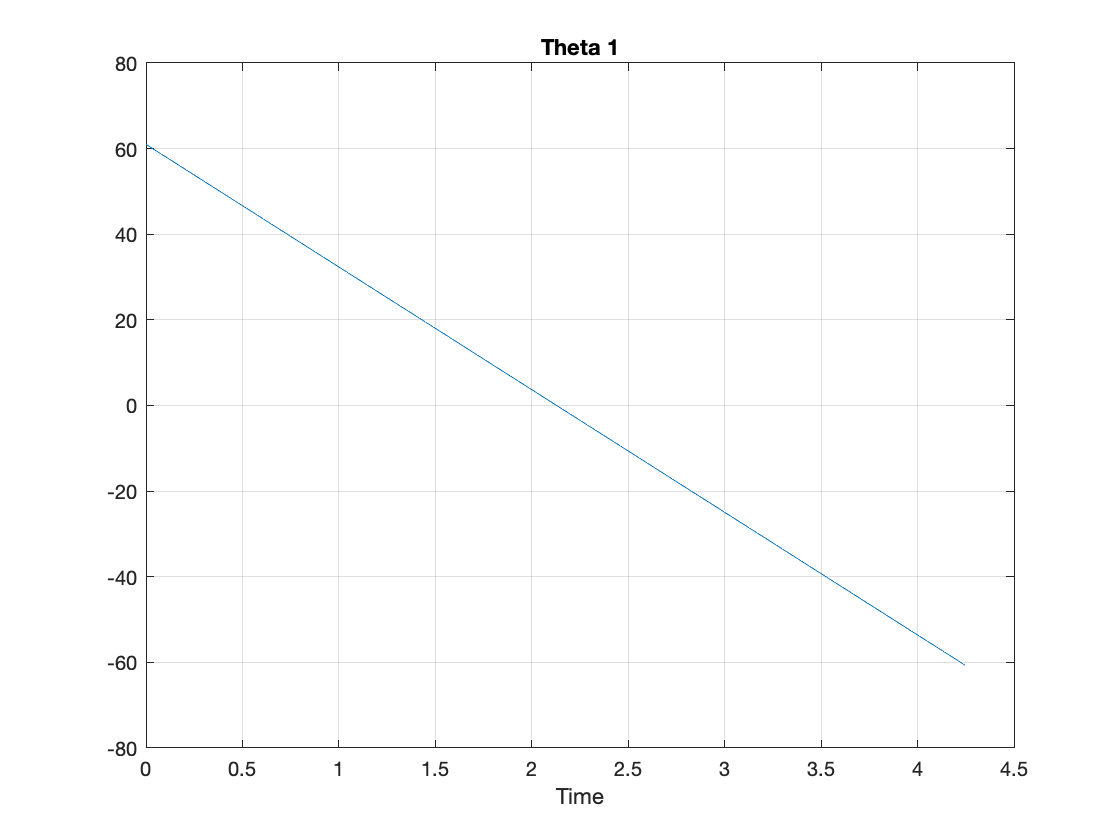


%Velocity
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    B = [-r1*w1*cosd(th1(i));...
        r1*w1*sind(th1(i))];
    x = A\B;
    w2(i) = x(1,1);
    w3(i) = x(2,1);
end

%Acceleration
for i = 1:length(th1)
    A = [ r2*cosd(th2(i)) ,- r3*cosd(th3(i));...
          -r2*sind(th2(i)) ,+ r3*sind(th3(i)) ];
    
    B = [r1*w1^2*sind(th1(i)) + r2*w2(i)^2*sind(th2(i)) - r3*w3(i)^2*sind(th3(i));...
        r1*w1^2*cosd(th1(i)) + r2*w2(i)^2*cosd(th2(i)) - r3*w3(i)^2*cosd(th3(i))];
    x = A\B;
    a2(i) = x(1,1);
    a3(i) = x(2,1);
end

t1 = t;
t1(1) = [];
w2(1) = [];
w3(1) = [];
a2(1) = [];
a3(1) = [];

plot(t,th1)
title("Theta 1")
xlabel("Time")
grid on

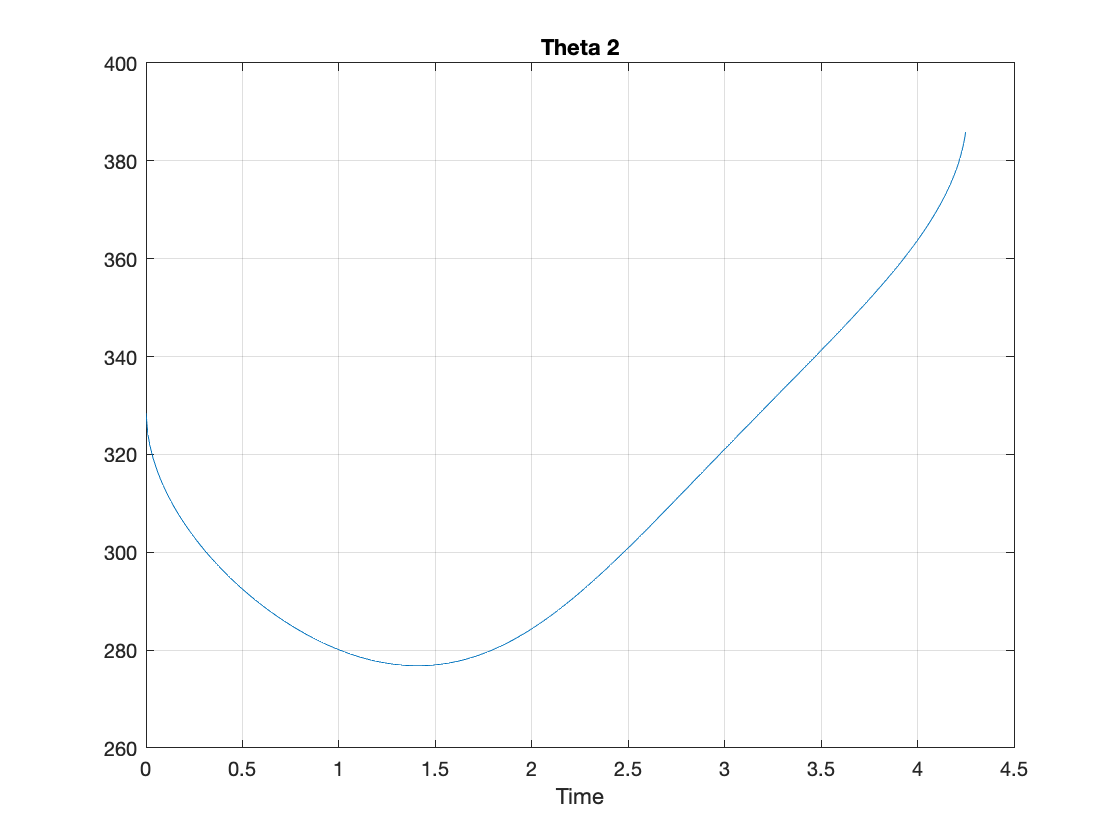


plot(t,th2)
title("Theta 2")
xlabel("Time")
grid on

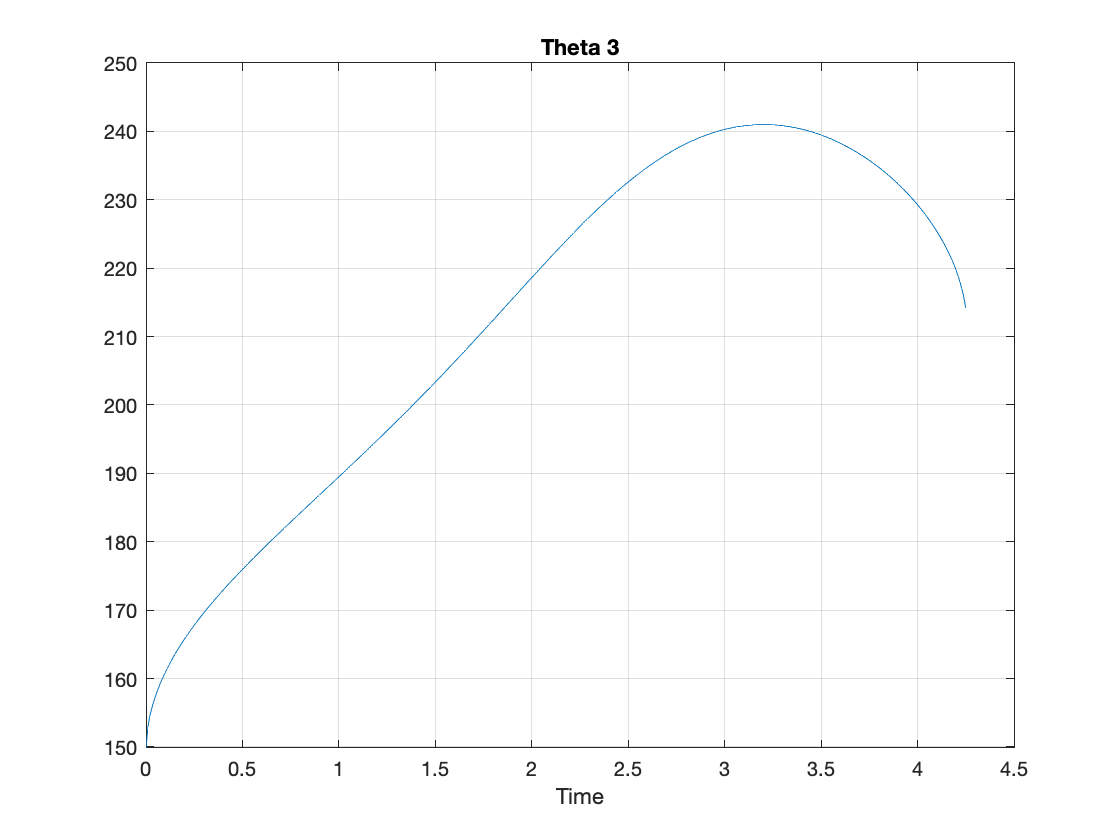


plot(t,th3)
title("Theta 3")
xlabel("Time")
grid on

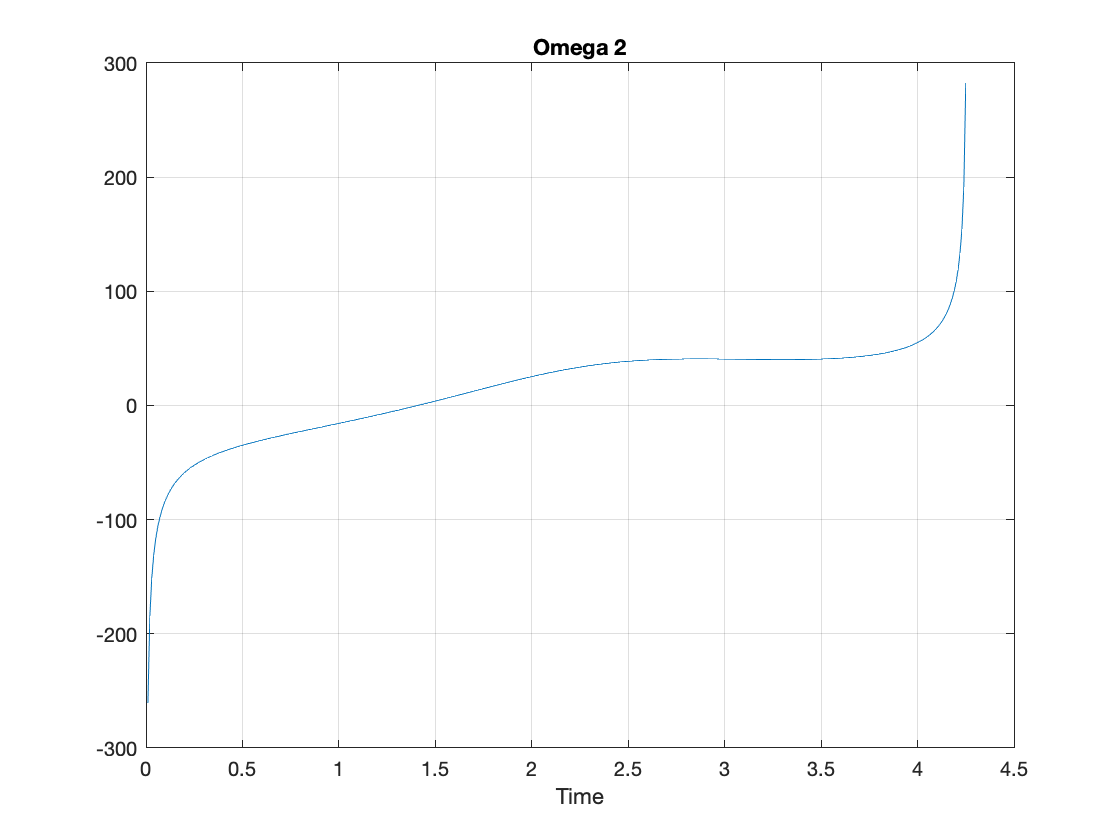



plot(t1,w2)
title("Omega 2")
xlabel("Time")
grid on

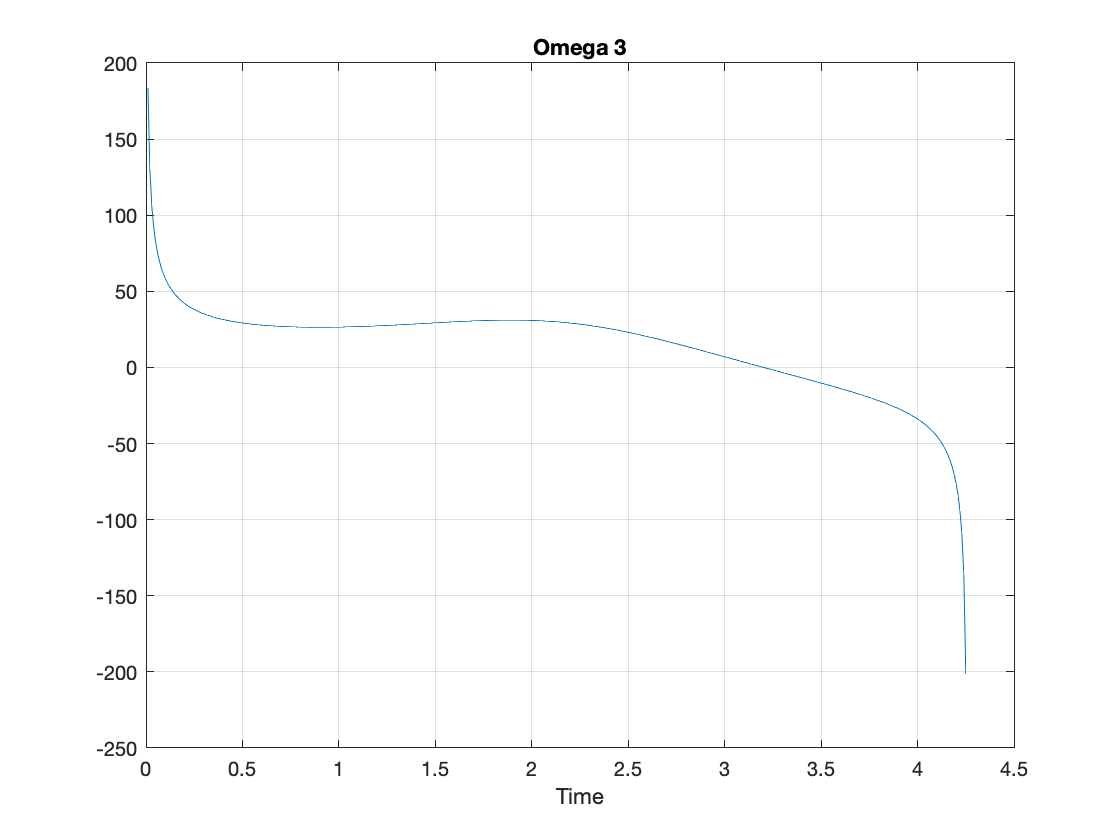



plot(t1,w3)
title("Omega 3")
xlabel("Time")
grid on

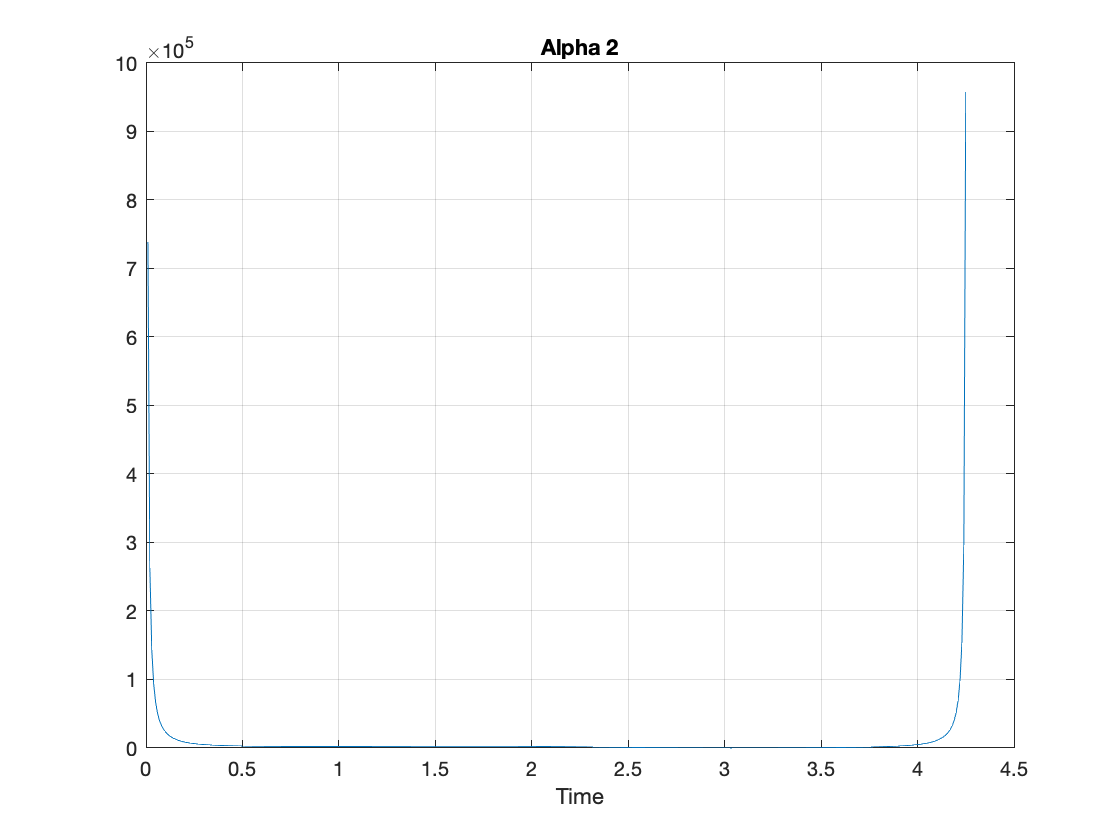



plot(t1,a2)
title("Alpha 2")
xlabel("Time")
grid on

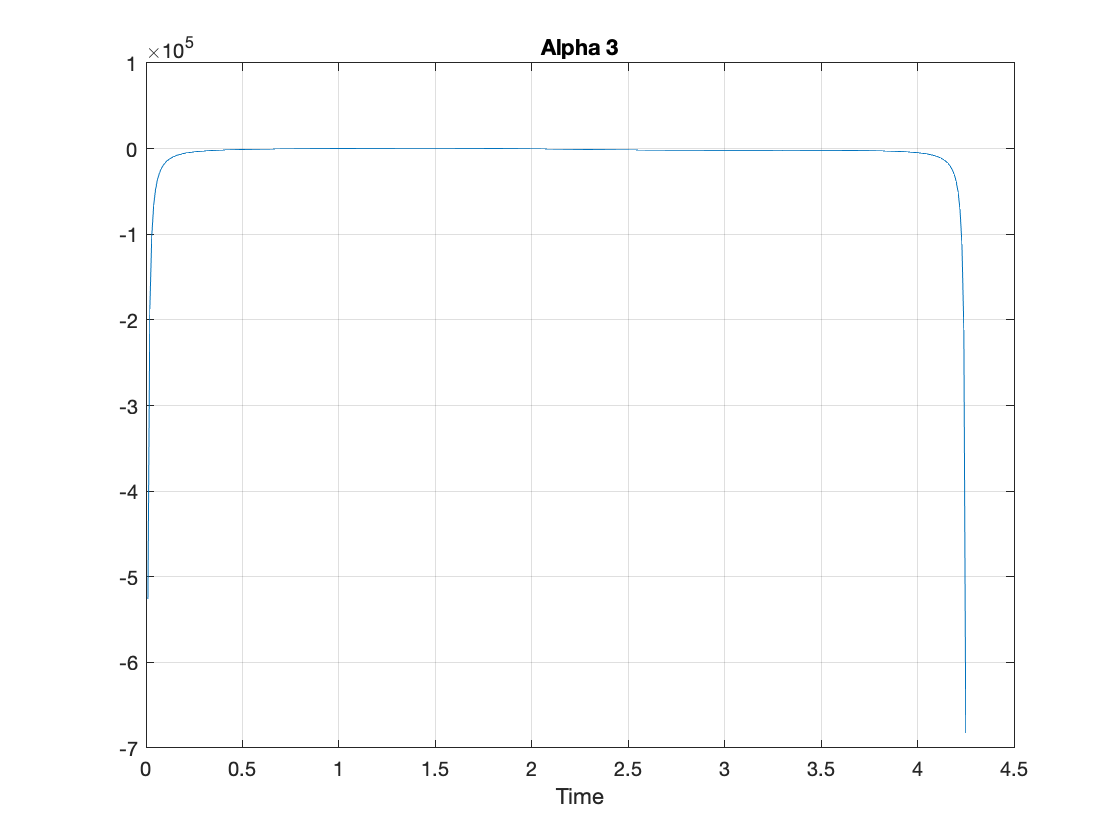


plot(t1,a3)
title("Alpha 3")
xlabel("Time")
grid on

r1i'

ans = 426×1
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000


r2i'

ans = 426×1
    3.2006
    3.2001
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000
    3.2000


r3i'

ans = 426×1
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
    4.5000
